# Commercial

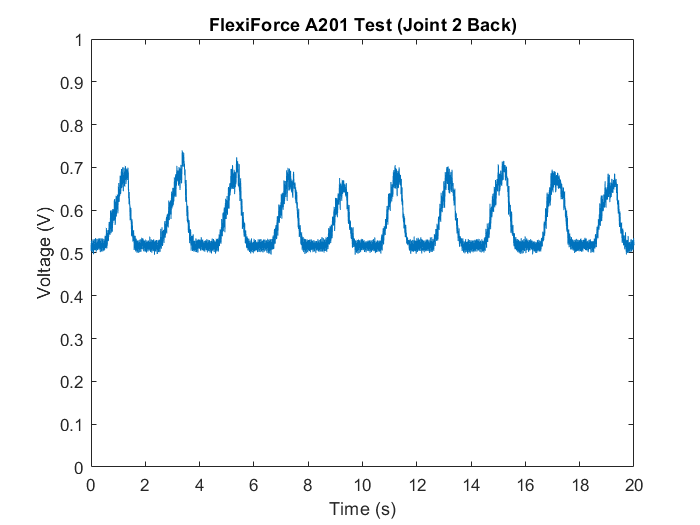

a=readmatrix("CommMidBack.xlsx","Range","B32000:B40000");
b=[0:1:8000];
plot(b./400,a)
%xlim([0 8000])
xlabel('Time (s)')
ylabel('Voltage (V)')
title('FlexiForce A201 Test (Joint 2 Back)')
ylim([0 1])

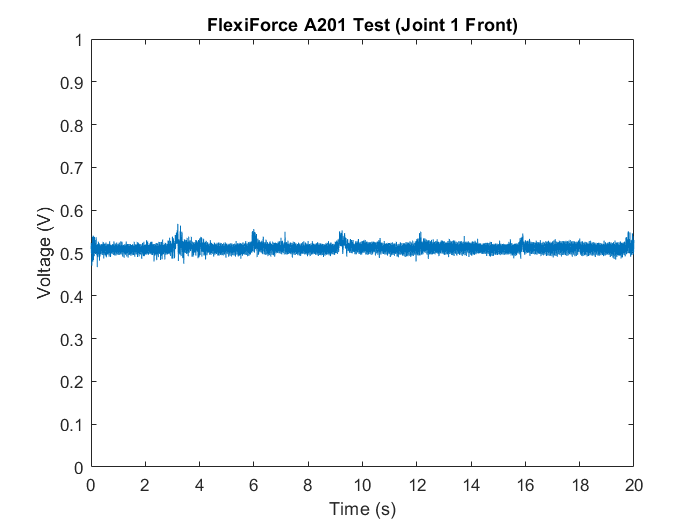


c=readmatrix("CommTopFront.xlsx","Range","B1:B8000");
d=[0:1:7999];
plot(d./400,c)
%xlim([0 8000])
xlabel('Time (s)')
ylabel('Voltage (V)')
title('FlexiForce A201 Test (Joint 1 Front)')
ylim([0 1])

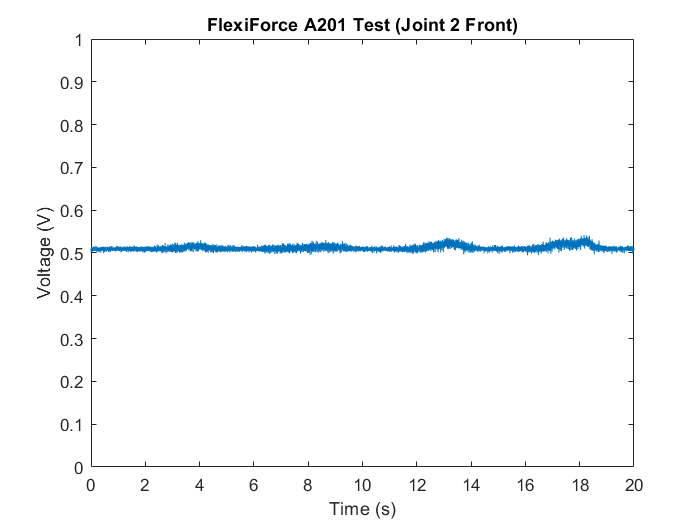



e=readmatrix("CommMidFront.xlsx","Range","B1501:B9500");
f=[0:1:7999];
plot(f./400,e)
%xlim([0 8000])
xlabel('Time (s)')
ylabel('Voltage (V)')
title('FlexiForce A201 Test (Joint 2 Front)')
ylim([0 1])

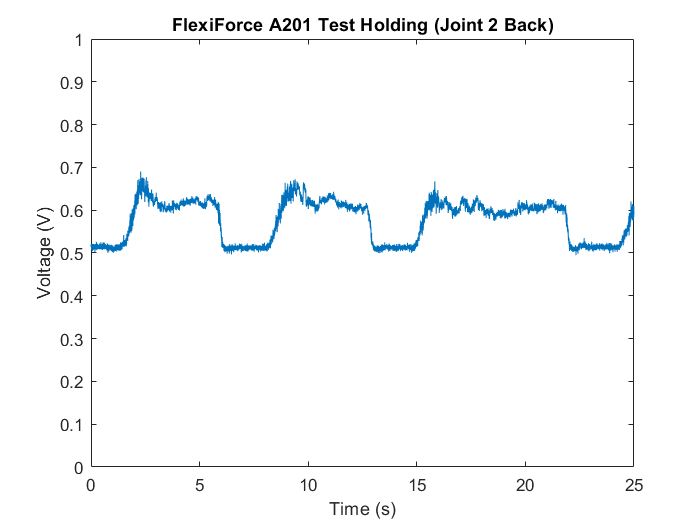



g=readmatrix("CommMidBackHold.xlsx","Range","B1:B10000");
h=[0:1:9999];
plot(h./400,g)
xlim([0 25])
xlabel('Time (s)')
ylabel('Voltage (V)')
title('FlexiForce A201 Test Holding (Joint 2 Back)')
ylim([0 1])

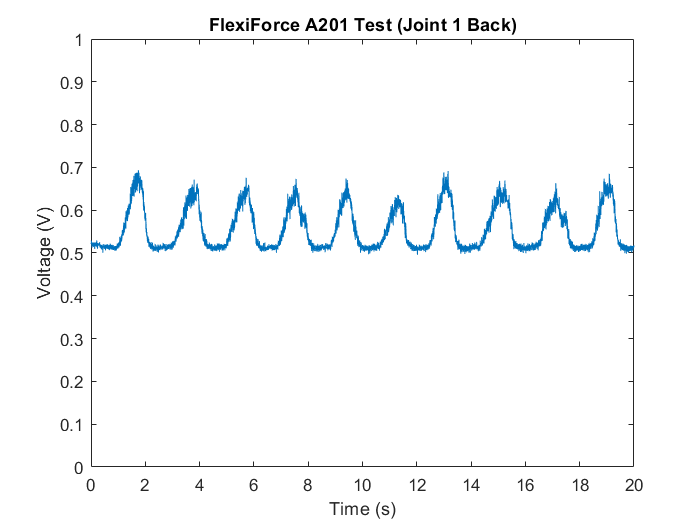



i=readmatrix("CommTopBack.xlsx","Range","B201:B8200");
j=[0:1:7999];
plot(j./400,i)
%xlim([0 9000])
xlabel('Time (s)')
ylabel('Voltage (V)')
title('FlexiForce A201 Test (Joint 1 Back)')
ylim([0 1])

## Screen Printed Tests

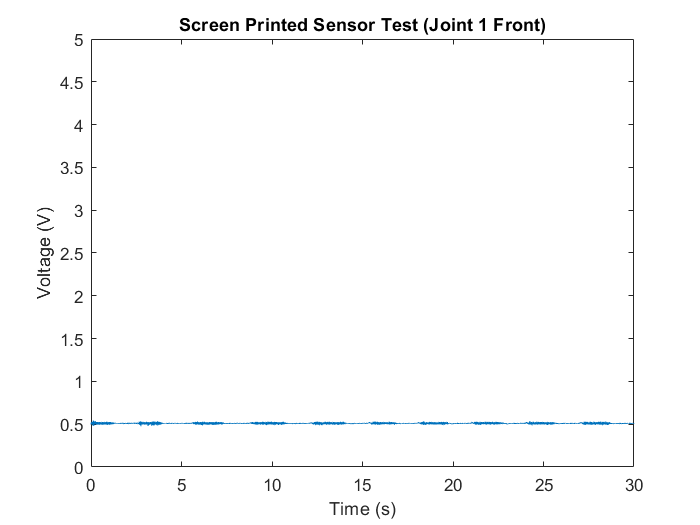

k=readmatrix("printedtopjointfront1.xlsx","Range","B1:B40000");
l=[0:1:39999];
plot(l./400,k)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Screen Printed Sensor Test (Joint 1 Front)')
ylim([0 5])
xlim([0 30])

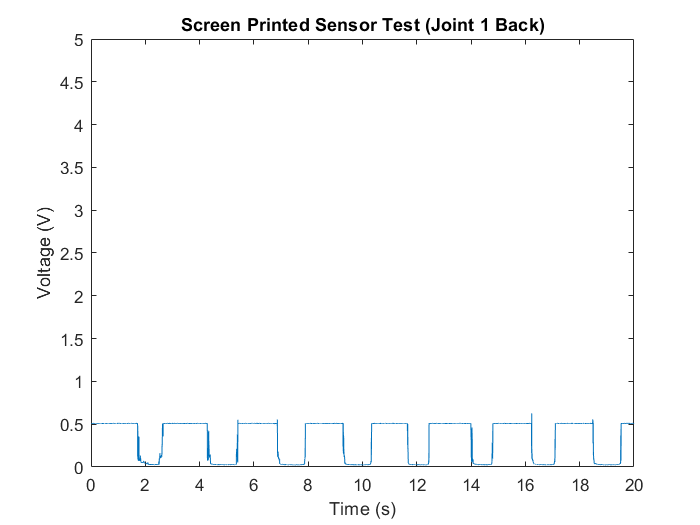



m=readmatrix("printedtopjointback1.xlsx","Range","B1:B8000");
n=[1:1:8000];
plot(n./400,m)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Screen Printed Sensor Test (Joint 1 Back)')
ylim([0 5])

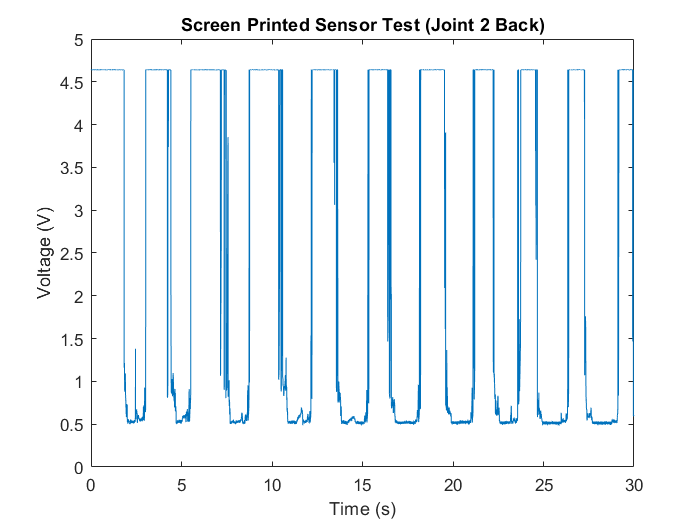


o=readmatrix("printedmidjointback.xlsx","Range","B1:B12000");
p=[1:1:12000];
plot(p./400,o)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Screen Printed Sensor Test (Joint 2 Back)')
ylim([0 5])

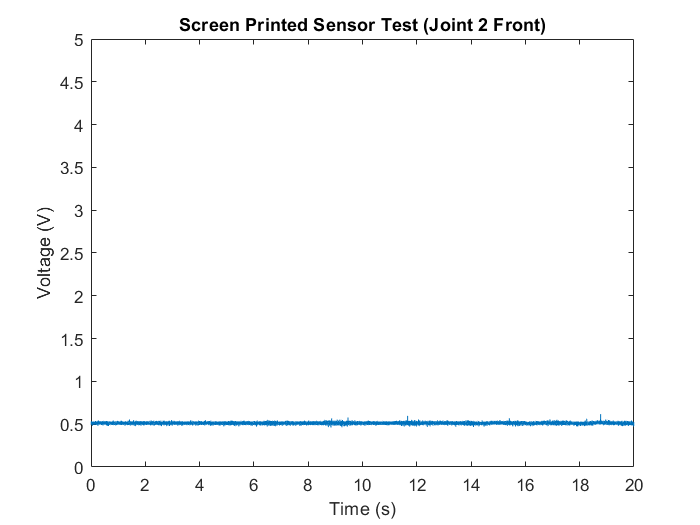


q=readmatrix("printedmidjointfront.xlsx","Range","B1:B8000");
r=[1:1:8000];
plot(r./400,q)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Screen Printed Sensor Test (Joint 2 Front)')
ylim([0 5])

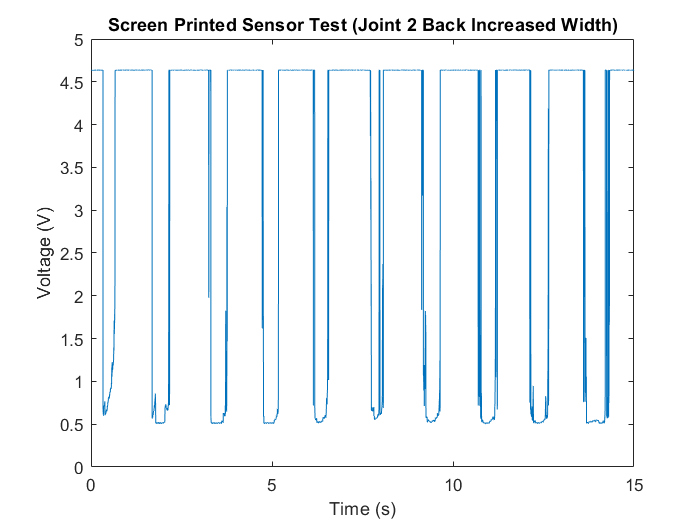


s=readmatrix("printedmidjointbackthick.xlsx","Range","B5001:B11000");
t=[1:1:6000];
plot(t./400,s)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Screen Printed Sensor Test (Joint 2 Back Increased Width)')
ylim([0 5])

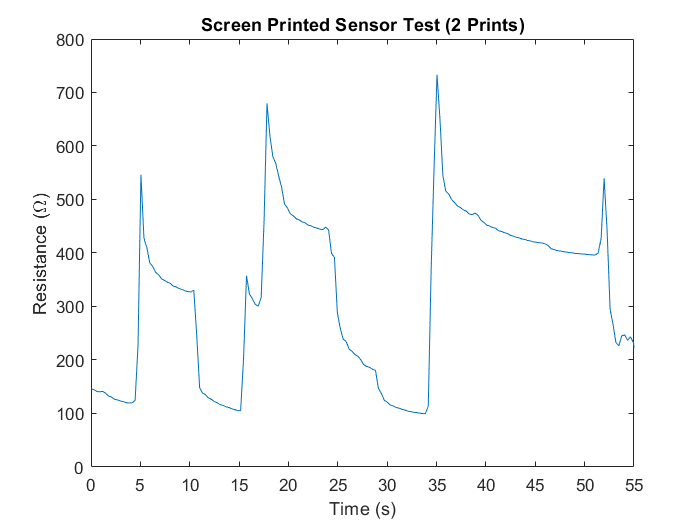

pr2=readmatrix("SPmid2print.xlsx","Range","B358:B548");
pr2t=readmatrix("SPmid2print.xlsx","Range","A1:A191");
pr2tt=[0:1:190];
plot(pr2t,pr2)
xlabel('Time (s)')
ylabel('Resistance (\Omega)')
title('Screen Printed Sensor Test (2 Prints)')
xlim([0 55])

## Screen Printed Bottom Knuckle

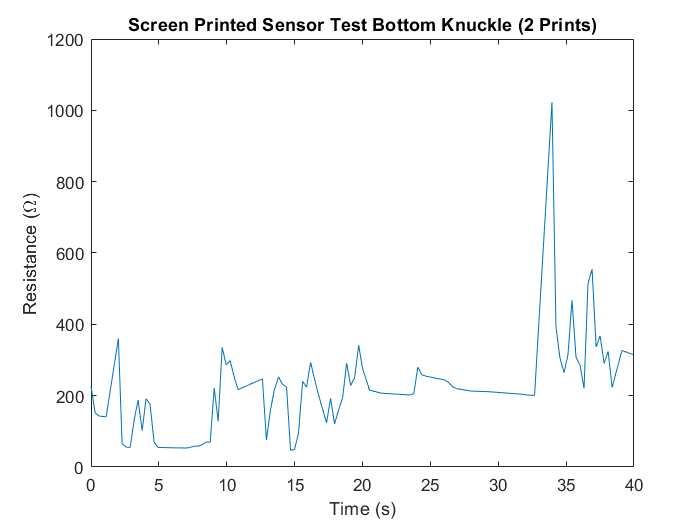

bpr2=readmatrix("spbottom.xlsx","Range","B200:B300");
bpr2t=readmatrix("spbottom.xlsx","Range","A1:A101");
bpr2tt=[0:1:100];
plot(bpr2t,bpr2)
xlabel('Time (s)')
ylabel('Resistance (\Omega)')
title('Screen Printed Sensor Test Bottom Knuckle (2 Prints)')
xlim([0 40])

## Foam CNF Sensors

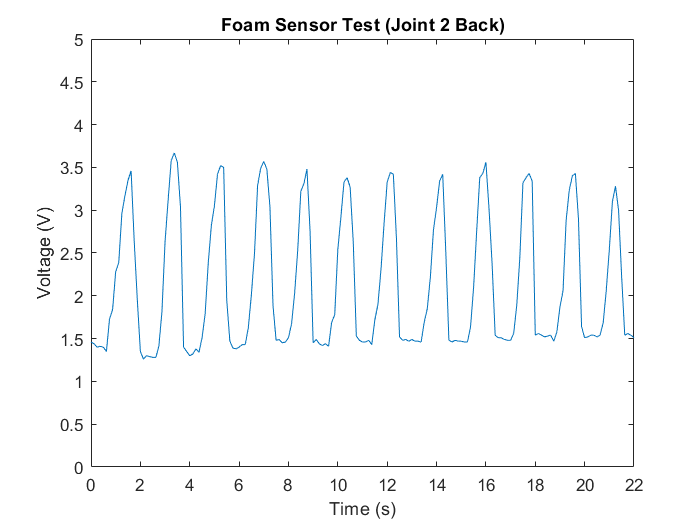

u=readmatrix("FoamTest.xlsx","Range","A2:KN2");
v=[0:1:180];
plot(v./8,u(8:188))
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Foam Sensor Test (Joint 2 Back)')
ylim([0 5])
xlim([0 22])

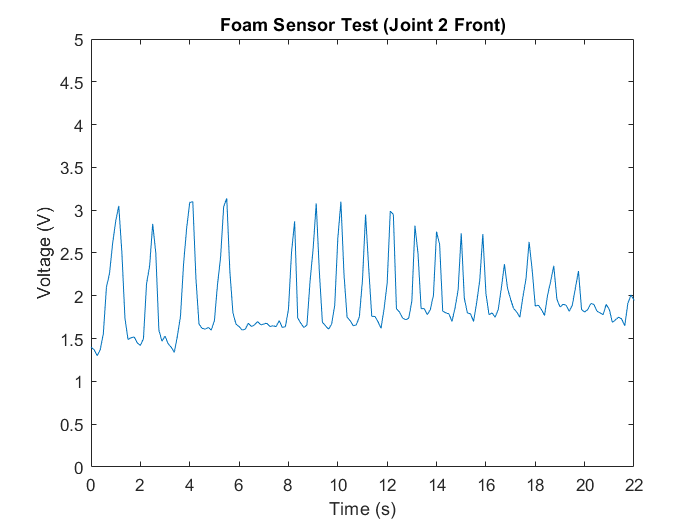


ff=readmatrix("FoamFrontTest.csv","Range","A9:KN9");
fftime=[0:1:180];
plot(fftime./8,ff(65:245))
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Foam Sensor Test (Joint 2 Front)')
ylim([0 5])
xlim([0 22])

## Bar Charts for each signal (FoamAmSL) NEW

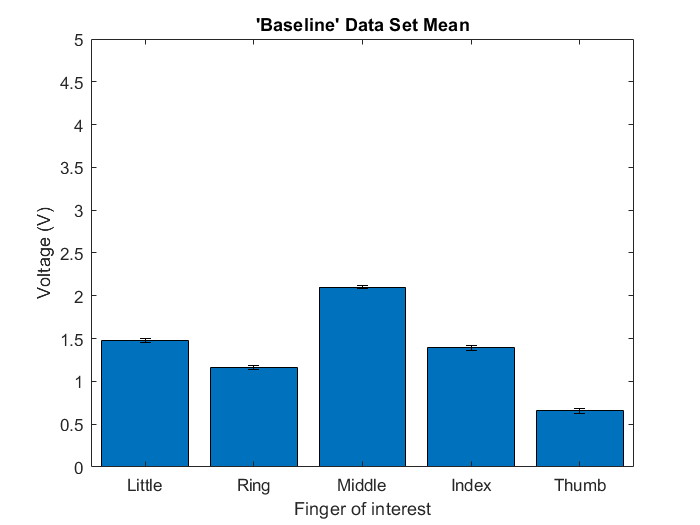

%names=categorical({'Pinky'; 'Ring'; 'Middle'; 'Index'; 'Thumb'});
%names = reordercats(names,{'Pinky'; 'Ring'; 'Middle'; 'Index'; 'Thumb'});
%Baseline
b0=readmatrix("FoamAmSL.csv","Range","C2:C11");
b1=readmatrix("FoamAmSL.csv","Range","D2:D11");
b2=readmatrix("FoamAmSL.csv","Range","E2:E11");
b3=readmatrix("FoamAmSL.csv","Range","F2:F11");
b4=readmatrix("FoamAmSL.csv","Range","G2:G11");
b5=[mean(b0),mean(b1),mean(b2),mean(b3),mean(b4)];
berr=[std(b0),std(b1),std(b2),std(b3),std(b4)];
bar(names,b5)
hold on
er=errorbar(names,b5,berr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Baseline'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

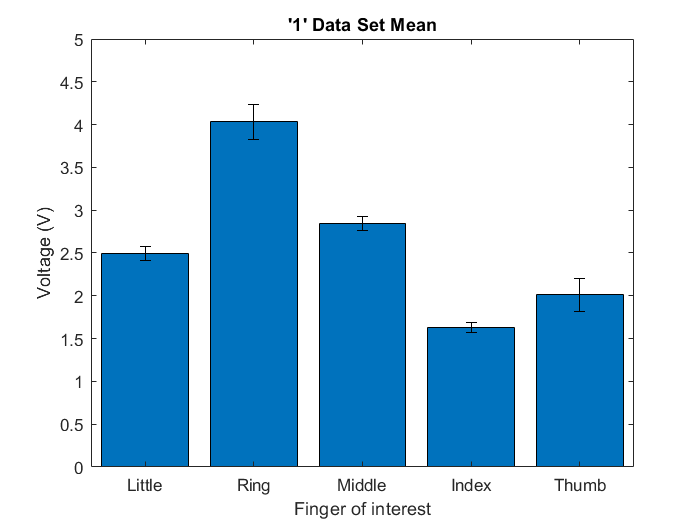


%1
one0=readmatrix("FoamAmSL.csv","Range","C12:C21");
one1=readmatrix("FoamAmSL.csv","Range","D12:D21");
one2=readmatrix("FoamAmSL.csv","Range","E12:E21");
one3=readmatrix("FoamAmSL.csv","Range","F12:F21");
one4=readmatrix("FoamAmSL.csv","Range","G12:G21");
one5=[mean(one0),mean(one1),mean(one2),mean(one3),mean(one4)];
oneerr=[std(one0),std(one1),std(one2),std(one3),std(one4)];
bar(names,one5)
hold on
er=errorbar(names,one5,oneerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''1'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

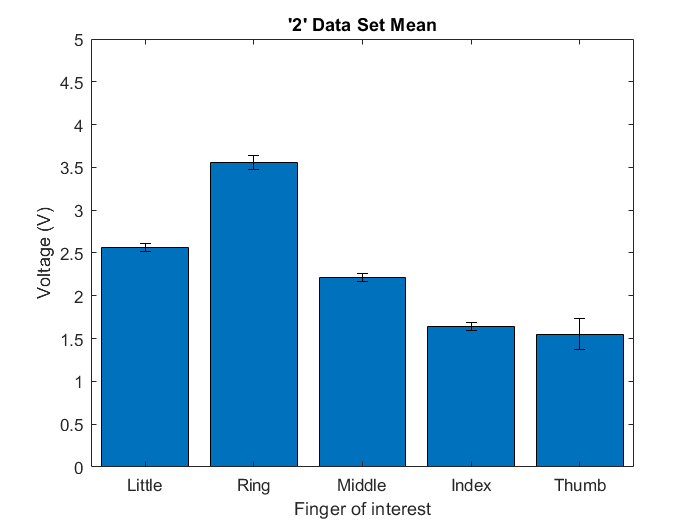



%2

two0=readmatrix("FoamAmSL.csv","Range","C22:C31");
two1=readmatrix("FoamAmSL.csv","Range","D22:D31");
two2=readmatrix("FoamAmSL.csv","Range","E22:E31");
two3=readmatrix("FoamAmSL.csv","Range","F22:F31");
two4=readmatrix("FoamAmSL.csv","Range","G22:G31");
two5=[mean(two0),mean(two1),mean(two2),mean(two3),mean(two4)];
twoerr=[std(two0),std(two1),std(two2),std(two3),std(two4)];
bar(names,two5)
hold on
er=errorbar(names,two5,twoerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''2'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

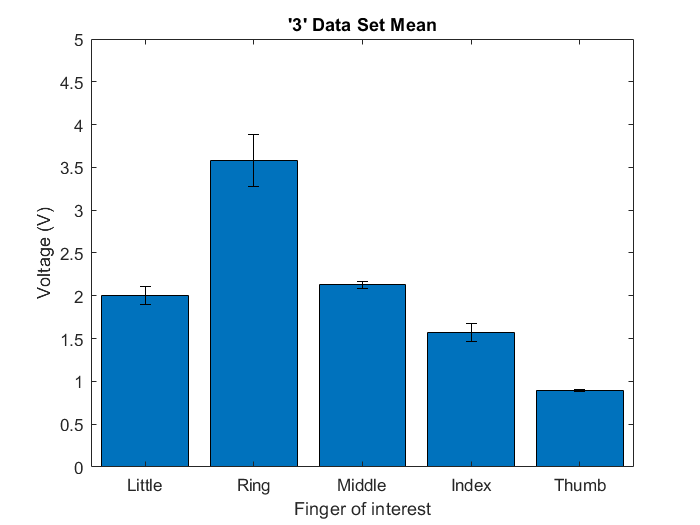



%3

thr0=readmatrix("FoamAmSL.csv","Range","C32:C41");
thr1=readmatrix("FoamAmSL.csv","Range","D32:D41");
thr2=readmatrix("FoamAmSL.csv","Range","E32:E41");
thr3=readmatrix("FoamAmSL.csv","Range","F32:F41");
thr4=readmatrix("FoamAmSL.csv","Range","G32:G41");
thr5=[mean(thr0),mean(thr1),mean(thr2),mean(thr3),mean(thr4)];
threrr=[std(thr0),std(thr1),std(thr2),std(thr3),std(thr4)];
bar(names,thr5)
hold on
er=errorbar(names,thr5,threrr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''3'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

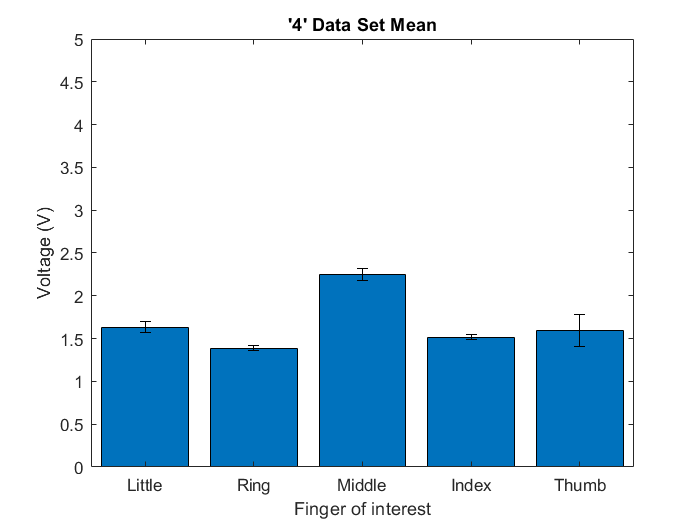



%4

four0=readmatrix("FoamAmSL.csv","Range","C42:C51");
four1=readmatrix("FoamAmSL.csv","Range","D42:D51");
four2=readmatrix("FoamAmSL.csv","Range","E42:E51");
four3=readmatrix("FoamAmSL.csv","Range","F42:F51");
four4=readmatrix("FoamAmSL.csv","Range","G42:G51");
four5=[mean(four0),mean(four1),mean(four2),mean(four3),mean(four4)];
fourerr=[std(four0),std(four1),std(four2),std(four3),std(four4)];
bar(names,four5)
hold on
er=errorbar(names,four5,fourerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''4'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

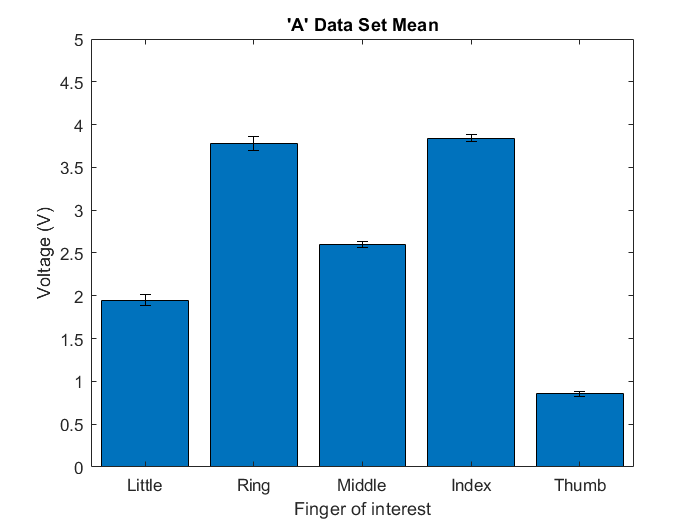



%A

a0=readmatrix("FoamAmSL.csv","Range","C52:C61");
a1=readmatrix("FoamAmSL.csv","Range","D52:D61");
a2=readmatrix("FoamAmSL.csv","Range","E52:E61");
a3=readmatrix("FoamAmSL.csv","Range","F52:F61");
a4=readmatrix("FoamAmSL.csv","Range","G52:G61");
a5=[mean(a0),mean(a1),mean(a2),mean(a3),mean(a4)];
aerr=[std(a0),std(a1),std(a2),std(a3),std(a4)];
bar(names,a5)
hold on
er=errorbar(names,a5,aerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''A'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

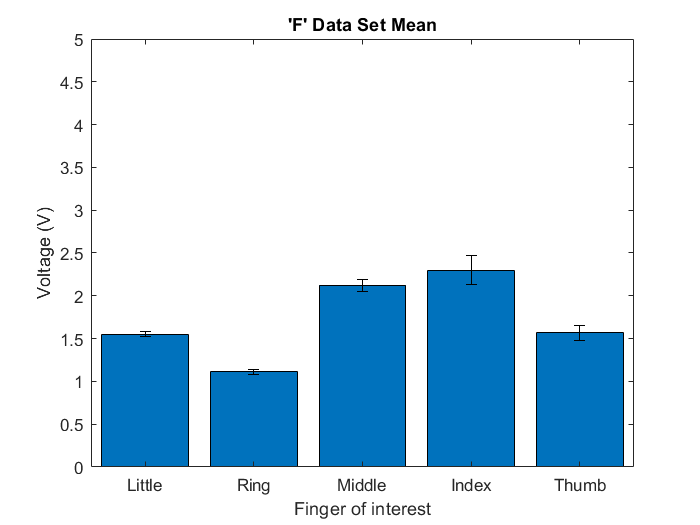



%F

f0=readmatrix("FoamAmSL.csv","Range","C62:C71");
f1=readmatrix("FoamAmSL.csv","Range","D62:D71");
f2=readmatrix("FoamAmSL.csv","Range","E62:E71");
f3=readmatrix("FoamAmSL.csv","Range","F62:F71");
f4=readmatrix("FoamAmSL.csv","Range","G62:G71");
f5=[mean(f0),mean(f1),mean(f2),mean(f3),mean(f4)];
ferr=[std(f0),std(f1),std(f2),std(f3),std(f4)];
bar(names,f5)
hold on
er=errorbar(names,f5,ferr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''F'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

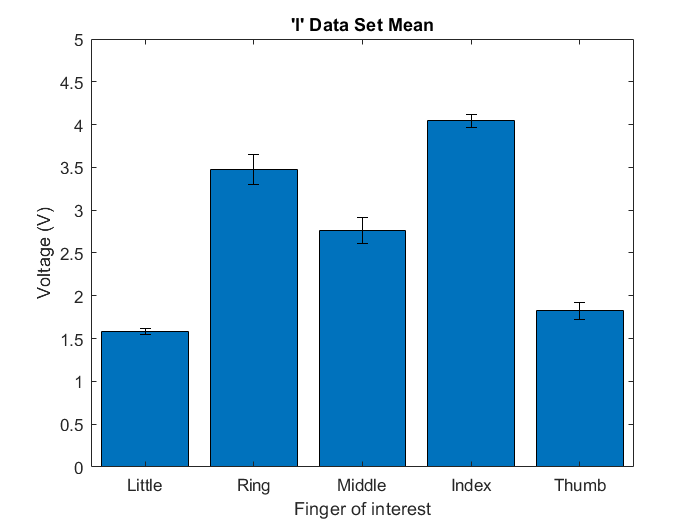



%I

i0=readmatrix("FoamAmSL.csv","Range","C72:C81");
i1=readmatrix("FoamAmSL.csv","Range","D72:D81");
i2=readmatrix("FoamAmSL.csv","Range","E72:E81");
i3=readmatrix("FoamAmSL.csv","Range","F72:F81");
i4=readmatrix("FoamAmSL.csv","Range","G72:G81");
i5=[mean(i0),mean(i1),mean(i2),mean(i3),mean(i4)];
ierr=[std(i0),std(i1),std(i2),std(i3),std(i4)];
bar(names,i5)
hold on
er=errorbar(names,i5,ierr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''I'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

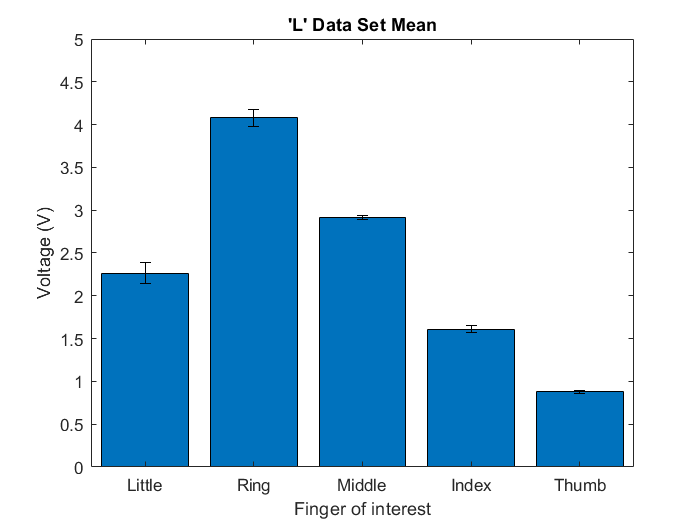



%L

l0=readmatrix("FoamAmSL.csv","Range","C82:C91");
l1=readmatrix("FoamAmSL.csv","Range","D82:D91");
l2=readmatrix("FoamAmSL.csv","Range","E82:E91");
l3=readmatrix("FoamAmSL.csv","Range","F82:F91");
l4=readmatrix("FoamAmSL.csv","Range","G82:G91");
l5=[mean(l0),mean(l1),mean(l2),mean(l3),mean(l4)];
lerr=[std(l0),std(l1),std(l2),std(l3),std(l4)];
bar(names,l5)
hold on
er=errorbar(names,l5,lerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''L'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

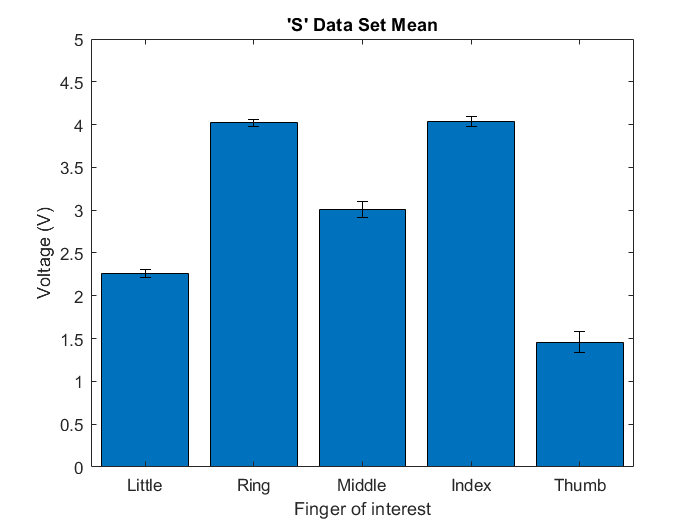



%s

s0=readmatrix("FoamAmSL.csv","Range","C92:C101");
s1=readmatrix("FoamAmSL.csv","Range","D92:D101");
s2=readmatrix("FoamAmSL.csv","Range","E92:E101");
s3=readmatrix("FoamAmSL.csv","Range","F92:F101");
s4=readmatrix("FoamAmSL.csv","Range","G92:G101");
s5=[mean(s0),mean(s1),mean(s2),mean(s3),mean(s4)];
serr=[std(s0),std(s1),std(s2),std(s3),std(s4)];
bar(names,s5)
hold on
er=errorbar(names,s5,serr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''S'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

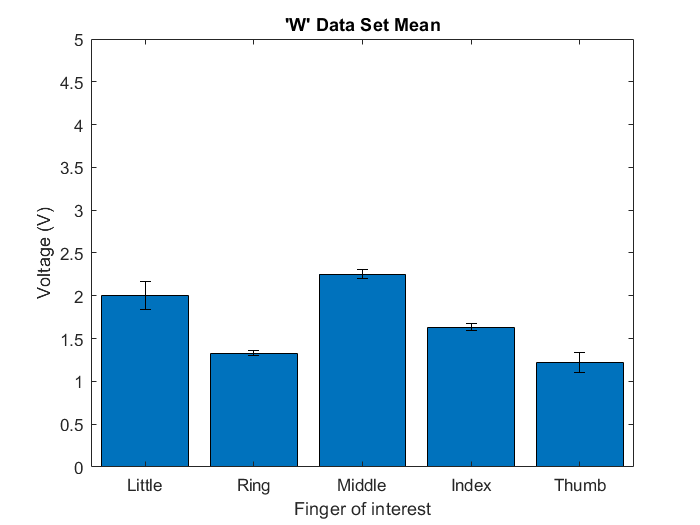



%W

w0=readmatrix("FoamAmSL.csv","Range","C102:C111");
w1=readmatrix("FoamAmSL.csv","Range","D102:D111");
w2=readmatrix("FoamAmSL.csv","Range","E102:E111");
w3=readmatrix("FoamAmSL.csv","Range","F102:F111");
w4=readmatrix("FoamAmSL.csv","Range","G102:G111");
w5=[mean(w0),mean(w1),mean(w2),mean(w3),mean(w4)];
werr=[std(w0),std(w1),std(w2),std(w3),std(w4)];
bar(names,w5)
hold on
er=errorbar(names,w5,werr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''W'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

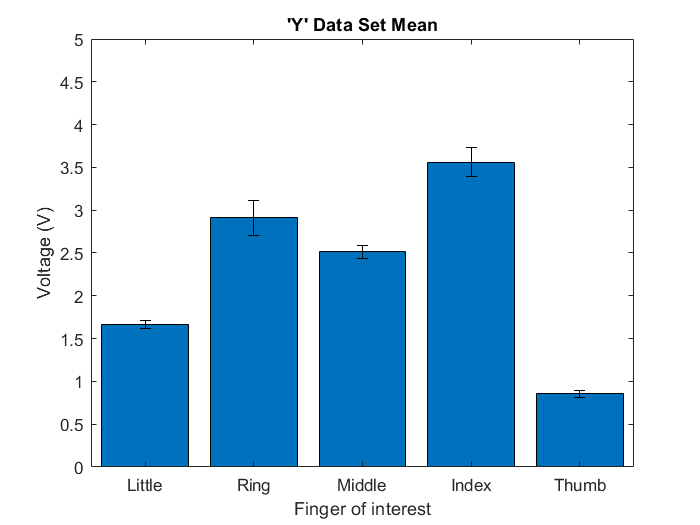



%Y

y0=readmatrix("FoamAmSL.csv","Range","C112:C121");
y1=readmatrix("FoamAmSL.csv","Range","D112:D121");
y2=readmatrix("FoamAmSL.csv","Range","E112:E121");
y3=readmatrix("FoamAmSL.csv","Range","F112:F121");
y4=readmatrix("FoamAmSL.csv","Range","G112:G121");
y5=[mean(y0),mean(y1),mean(y2),mean(y3),mean(y4)];
yerr=[std(y0),std(y1),std(y2),std(y3),std(y4)];
bar(names,y5)
hold on
er=errorbar(names,y5,yerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Y'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

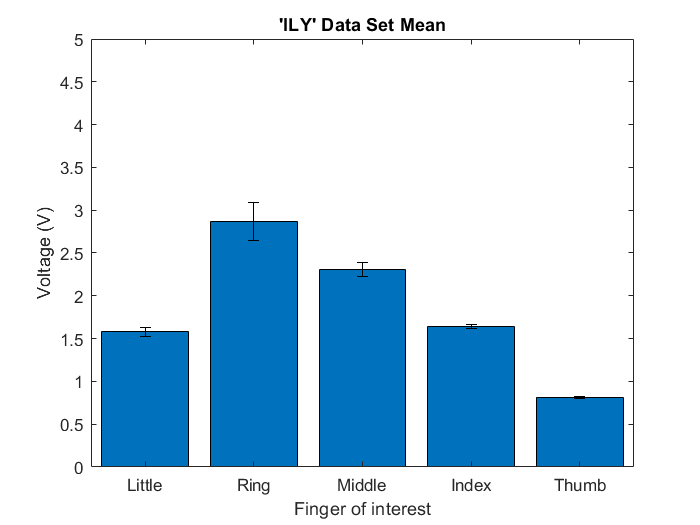



%ILY

ily0=readmatrix("FoamAmSL.csv","Range","C122:C131");
ily1=readmatrix("FoamAmSL.csv","Range","D122:D131");
ily2=readmatrix("FoamAmSL.csv","Range","E122:E131");
ily3=readmatrix("FoamAmSL.csv","Range","F122:F131");
ily4=readmatrix("FoamAmSL.csv","Range","G122:G131");
ily5=[mean(ily0),mean(ily1),mean(ily2),mean(ily3),mean(ily4)];
ilyerr=[std(ily0),std(ily1),std(ily2),std(ily3),std(ily4)];
bar(names,ily5)
hold on
er=errorbar(names,ily5,ilyerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''ILY'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

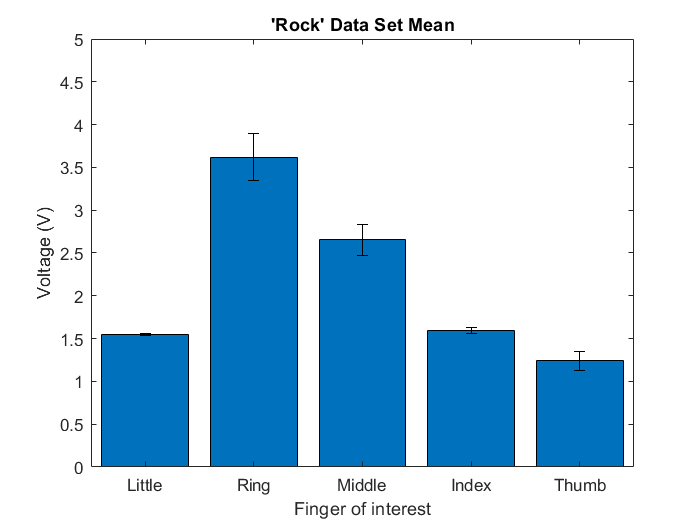



%Rock

rock0=readmatrix("FoamAmSL.csv","Range","C132:C141");
rock1=readmatrix("FoamAmSL.csv","Range","D132:D141");
rock2=readmatrix("FoamAmSL.csv","Range","E132:E141");
rock3=readmatrix("FoamAmSL.csv","Range","F132:F141");
rock4=readmatrix("FoamAmSL.csv","Range","G132:G141");
rock5=[mean(rock0),mean(rock1),mean(rock2),mean(rock3),mean(rock4)];
rockerr=[std(rock0),std(rock1),std(rock2),std(rock3),std(rock4)];
bar(names,rock5)
hold on
er=errorbar(names,rock5,rockerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Rock'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

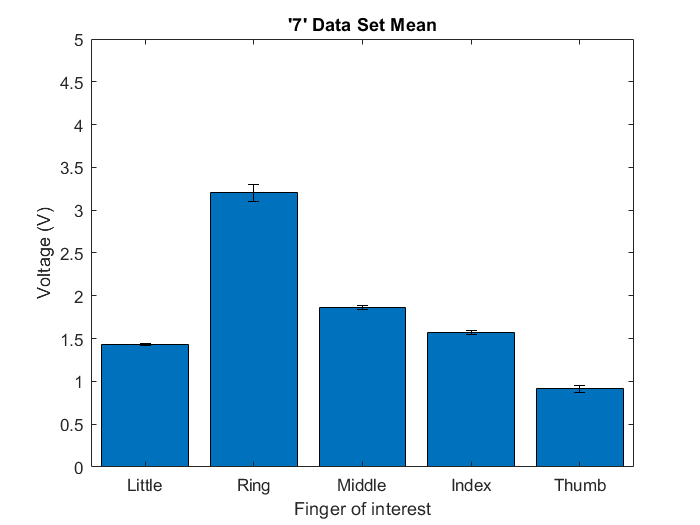



%7

sev0=readmatrix("FoamAmSL.csv","Range","C142:C151");
sev1=readmatrix("FoamAmSL.csv","Range","D142:D151");
sev2=readmatrix("FoamAmSL.csv","Range","E142:E151");
sev3=readmatrix("FoamAmSL.csv","Range","F142:F151");
sev4=readmatrix("FoamAmSL.csv","Range","G142:G151");
sev5=[mean(sev0),mean(sev1),mean(sev2),mean(sev3),mean(sev4)];
severr=[std(sev0),std(sev1),std(sev2),std(sev3),std(sev4)];
bar(names,sev5)
hold on
er=errorbar(names,sev5,severr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''7'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

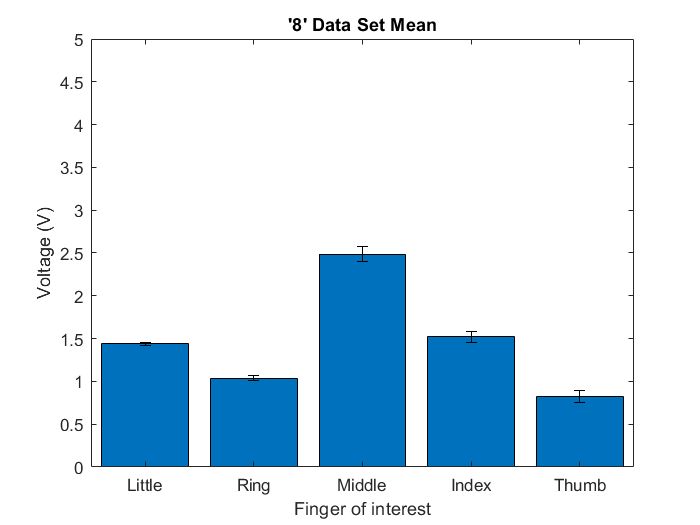



%8

eig0=readmatrix("FoamAmSL.csv","Range","C152:C161");
eig1=readmatrix("FoamAmSL.csv","Range","D152:D161");
eig2=readmatrix("FoamAmSL.csv","Range","E152:E161");
eig3=readmatrix("FoamAmSL.csv","Range","F152:F161");
eig4=readmatrix("FoamAmSL.csv","Range","G152:G161");
eig5=[mean(eig0),mean(eig1),mean(eig2),mean(eig3),mean(eig4)];
eigerr=[std(eig0),std(eig1),std(eig2),std(eig3),std(eig4)];
bar(names,eig5)
hold on
er=errorbar(names,eig5,eigerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''8'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

## Bar Charts for each signal (FlexiAmSL) NEW

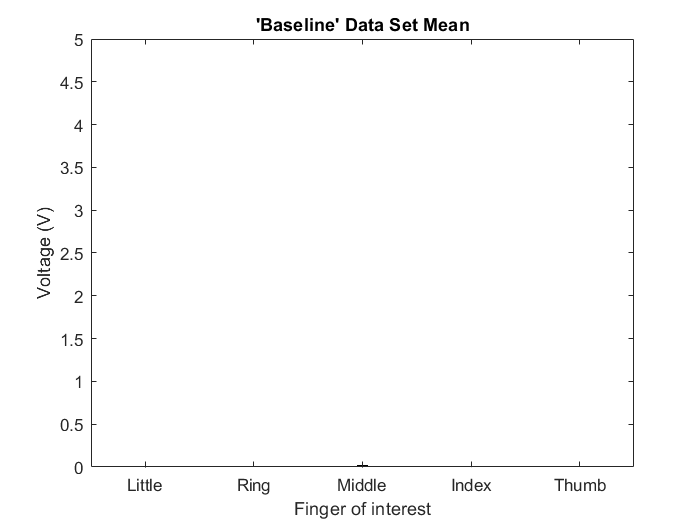

%names=categorical({'Pinky'; 'Ring'; 'Middle'; 'Index'; 'Thumb'});
%names = reordercats(names,{'Pinky'; 'Ring'; 'Middle'; 'Index'; 'Thumb'});
%Baseline
b0=readmatrix("FlexiAmSL.csv","Range","C2:C11");
b1=readmatrix("FlexiAmSL.csv","Range","D2:D11");
b2=readmatrix("FlexiAmSL.csv","Range","E2:E11");
b3=readmatrix("FlexiAmSL.csv","Range","F2:F11");
b4=readmatrix("FlexiAmSL.csv","Range","G2:G11");
b5=[mean(b0),mean(b1),mean(b2),mean(b3),mean(b4)];
berr=[std(b0),std(b1),std(b2),std(b3),std(b4)];
bar(names,b5)
hold on
er=errorbar(names,b5,berr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Baseline'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

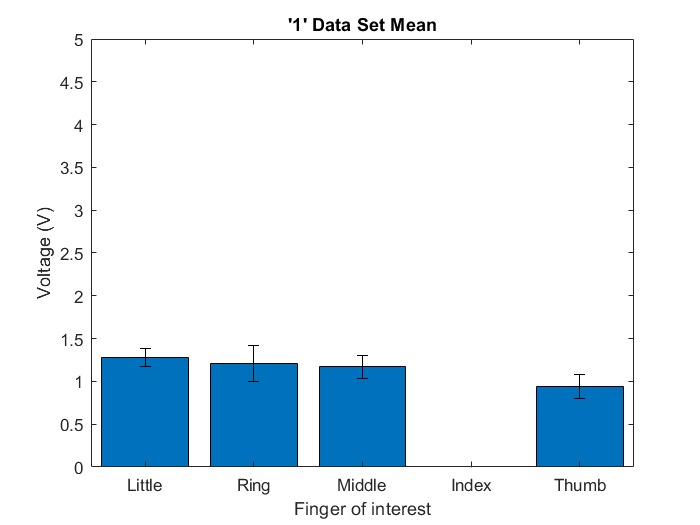


%1
one0=readmatrix("FlexiAmSL.csv","Range","C12:C21");
one1=readmatrix("FlexiAmSL.csv","Range","D12:D21");
one2=readmatrix("FlexiAmSL.csv","Range","E12:E21");
one3=readmatrix("FlexiAmSL.csv","Range","F12:F21");
one4=readmatrix("FlexiAmSL.csv","Range","G12:G21");
one5=[mean(one0),mean(one1),mean(one2),mean(one3),mean(one4)];
oneerr=[std(one0),std(one1),std(one2),std(one3),std(one4)];
bar(names,one5)
hold on
er=errorbar(names,one5,oneerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''1'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

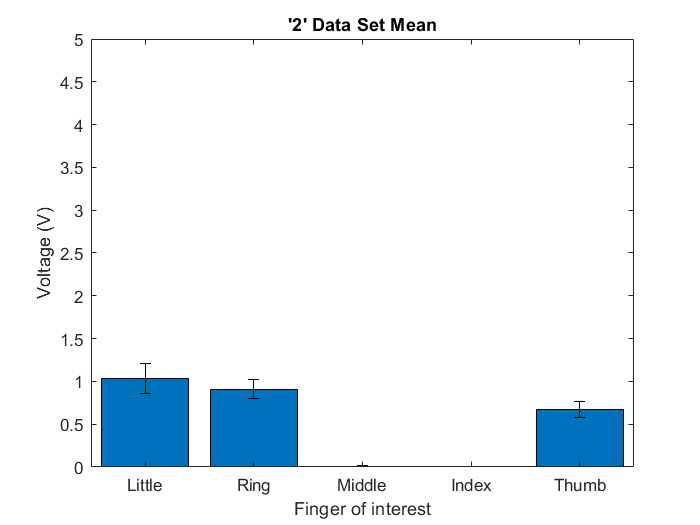



%2

two0=readmatrix("FlexiAmSL.csv","Range","C22:C31");
two1=readmatrix("FlexiAmSL.csv","Range","D22:D31");
two2=readmatrix("FlexiAmSL.csv","Range","E22:E31");
two3=readmatrix("FlexiAmSL.csv","Range","F22:F31");
two4=readmatrix("FlexiAmSL.csv","Range","G22:G31");
two5=[mean(two0),mean(two1),mean(two2),mean(two3),mean(two4)];
twoerr=[std(two0),std(two1),std(two2),std(two3),std(two4)];
bar(names,two5)
hold on
er=errorbar(names,two5,twoerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''2'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

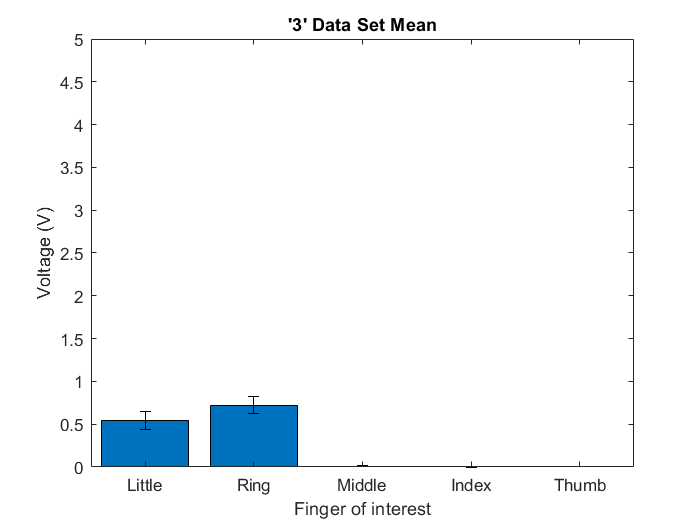



%3

thr0=readmatrix("FlexiAmSL.csv","Range","C32:C41");
thr1=readmatrix("FlexiAmSL.csv","Range","D32:D41");
thr2=readmatrix("FlexiAmSL.csv","Range","E32:E41");
thr3=readmatrix("FlexiAmSL.csv","Range","F32:F41");
thr4=readmatrix("FlexiAmSL.csv","Range","G32:G41");
thr5=[mean(thr0),mean(thr1),mean(thr2),mean(thr3),mean(thr4)];
threrr=[std(thr0),std(thr1),std(thr2),std(thr3),std(thr4)];
bar(names,thr5)
hold on
er=errorbar(names,thr5,threrr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''3'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

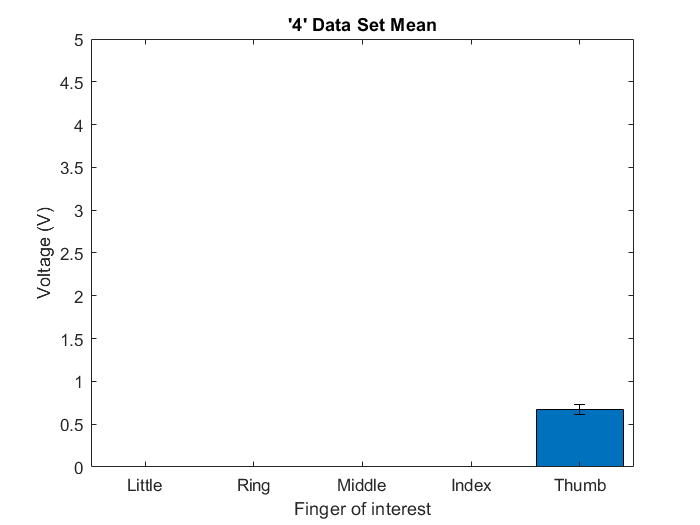



%4

four0=readmatrix("FlexiAmSL.csv","Range","C42:C51");
four1=readmatrix("FlexiAmSL.csv","Range","D42:D51");
four2=readmatrix("FlexiAmSL.csv","Range","E42:E51");
four3=readmatrix("FlexiAmSL.csv","Range","F42:F51");
four4=readmatrix("FlexiAmSL.csv","Range","G42:G51");
four5=[mean(four0),mean(four1),mean(four2),mean(four3),mean(four4)];
fourerr=[std(four0),std(four1),std(four2),std(four3),std(four4)];
bar(names,four5)
hold on
er=errorbar(names,four5,fourerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''4'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

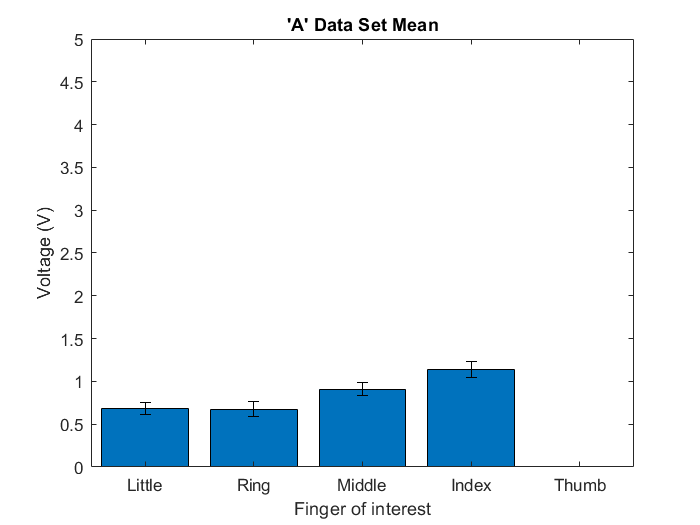



%A

a0=readmatrix("FlexiAmSL.csv","Range","C52:C61");
a1=readmatrix("FlexiAmSL.csv","Range","D52:D61");
a2=readmatrix("FlexiAmSL.csv","Range","E52:E61");
a3=readmatrix("FlexiAmSL.csv","Range","F52:F61");
a4=readmatrix("FlexiAmSL.csv","Range","G52:G61");
a5=[mean(a0),mean(a1),mean(a2),mean(a3),mean(a4)];
aerr=[std(a0),std(a1),std(a2),std(a3),std(a4)];
bar(names,a5)
hold on
er=errorbar(names,a5,aerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''A'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

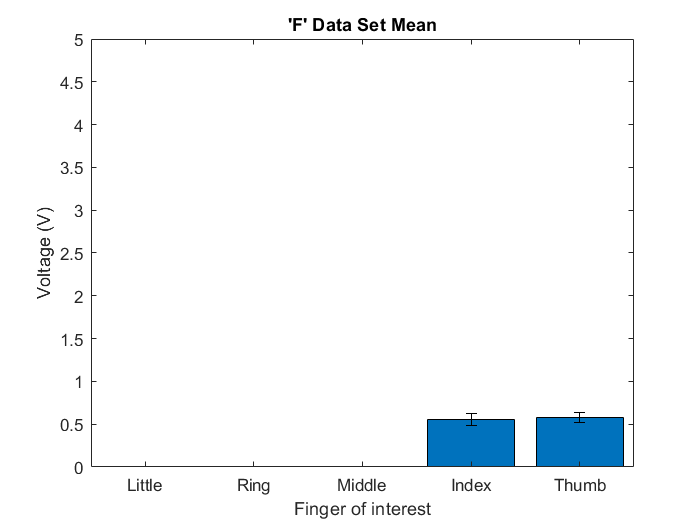



%F

f0=readmatrix("FlexiAmSL.csv","Range","C62:C71");
f1=readmatrix("FlexiAmSL.csv","Range","D62:D71");
f2=readmatrix("FlexiAmSL.csv","Range","E62:E71");
f3=readmatrix("FlexiAmSL.csv","Range","F62:F71");
f4=readmatrix("FlexiAmSL.csv","Range","G62:G71");
f5=[mean(f0),mean(f1),mean(f2),mean(f3),mean(f4)];
ferr=[std(f0),std(f1),std(f2),std(f3),std(f4)];
bar(names,f5)
hold on
er=errorbar(names,f5,ferr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''F'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

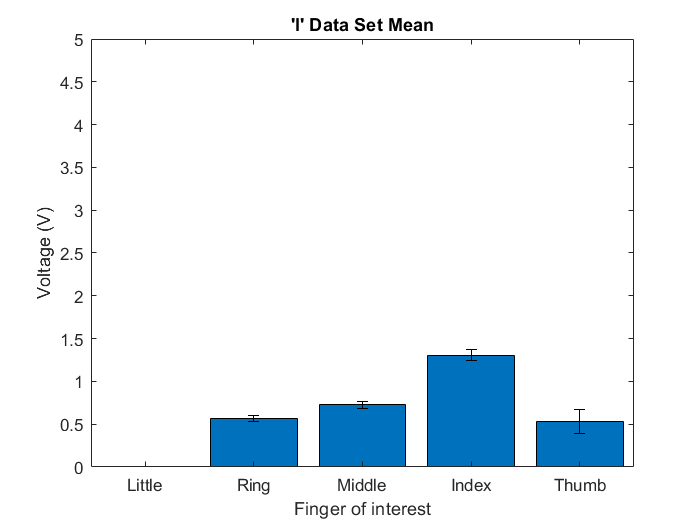



%I

i0=readmatrix("FlexiAmSL.csv","Range","C72:C81");
i1=readmatrix("FlexiAmSL.csv","Range","D72:D81");
i2=readmatrix("FlexiAmSL.csv","Range","E72:E81");
i3=readmatrix("FlexiAmSL.csv","Range","F72:F81");
i4=readmatrix("FlexiAmSL.csv","Range","G72:G81");
i5=[mean(i0),mean(i1),mean(i2),mean(i3),mean(i4)];
ierr=[std(i0),std(i1),std(i2),std(i3),std(i4)];
bar(names,i5)
hold on
er=errorbar(names,i5,ierr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''I'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

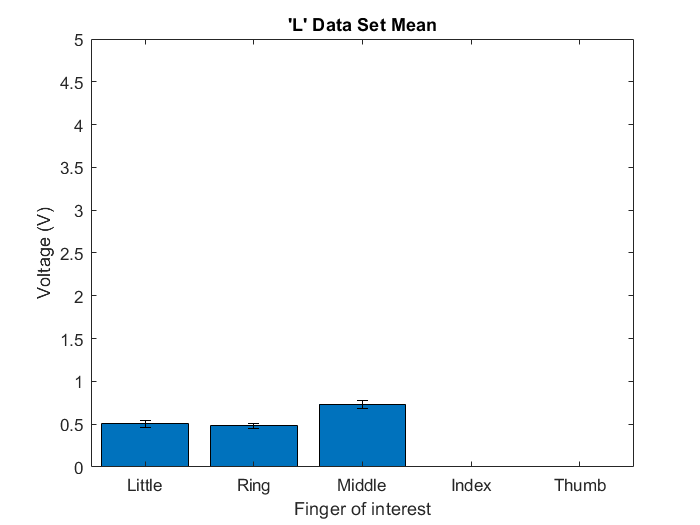



%L

l0=readmatrix("FlexiAmSL.csv","Range","C82:C91");
l1=readmatrix("FlexiAmSL.csv","Range","D82:D91");
l2=readmatrix("FlexiAmSL.csv","Range","E82:E91");
l3=readmatrix("FlexiAmSL.csv","Range","F82:F91");
l4=readmatrix("FlexiAmSL.csv","Range","G82:G91");
l5=[mean(l0),mean(l1),mean(l2),mean(l3),mean(l4)];
lerr=[std(l0),std(l1),std(l2),std(l3),std(l4)];
bar(names,l5)
hold on
er=errorbar(names,l5,lerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''L'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

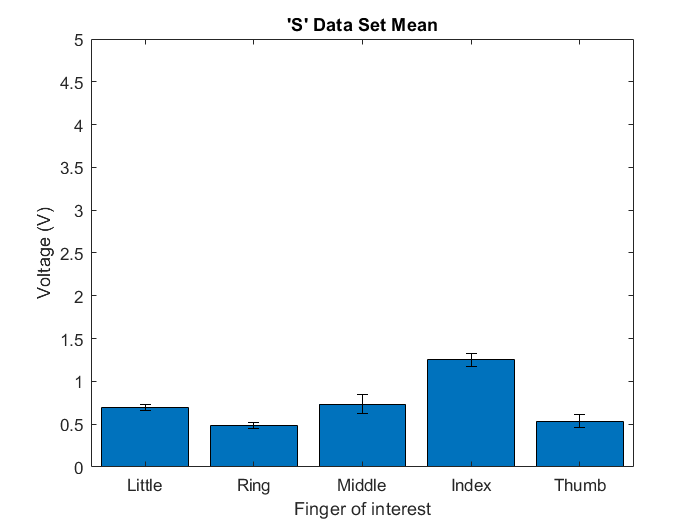



%s

s0=readmatrix("FlexiAmSL.csv","Range","C92:C101");
s1=readmatrix("FlexiAmSL.csv","Range","D92:D101");
s2=readmatrix("FlexiAmSL.csv","Range","E92:E101");
s3=readmatrix("FlexiAmSL.csv","Range","F92:F101");
s4=readmatrix("FlexiAmSL.csv","Range","G92:G101");
s5=[mean(s0),mean(s1),mean(s2),mean(s3),mean(s4)];
serr=[std(s0),std(s1),std(s2),std(s3),std(s4)];
bar(names,s5)
hold on
er=errorbar(names,s5,serr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''S'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

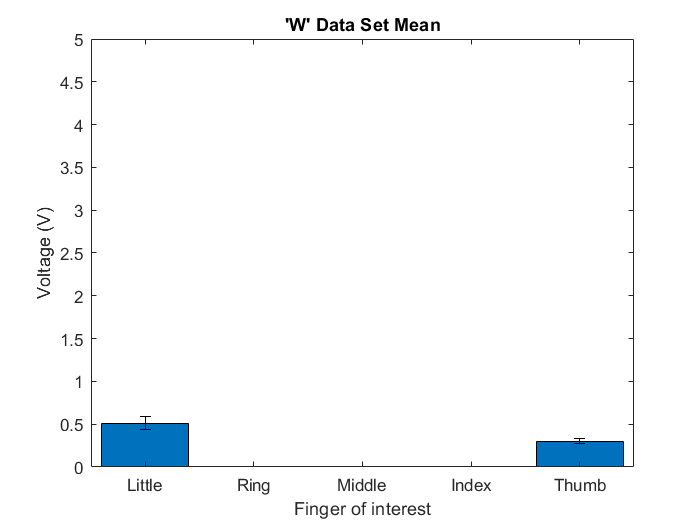



%W

w0=readmatrix("FlexiAmSL.csv","Range","C102:C111");
w1=readmatrix("FlexiAmSL.csv","Range","D102:D111");
w2=readmatrix("FlexiAmSL.csv","Range","E102:E111");
w3=readmatrix("FlexiAmSL.csv","Range","F102:F111");
w4=readmatrix("FlexiAmSL.csv","Range","G102:G111");
w5=[mean(w0),mean(w1),mean(w2),mean(w3),mean(w4)];
werr=[std(w0),std(w1),std(w2),std(w3),std(w4)];
bar(names,w5)
hold on
er=errorbar(names,w5,werr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''W'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

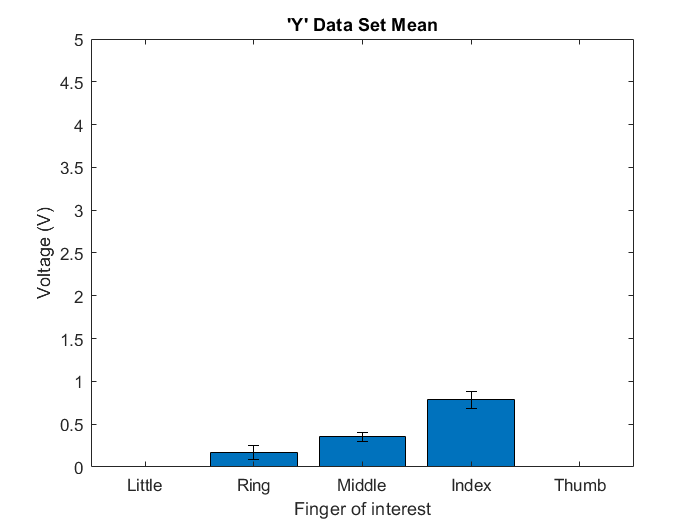



%Y

y0=readmatrix("FlexiAmSL.csv","Range","C112:C121");
y1=readmatrix("FlexiAmSL.csv","Range","D112:D121");
y2=readmatrix("FlexiAmSL.csv","Range","E112:E121");
y3=readmatrix("FlexiAmSL.csv","Range","F112:F121");
y4=readmatrix("FlexiAmSL.csv","Range","G112:G121");
y5=[mean(y0),mean(y1),mean(y2),mean(y3),mean(y4)];
yerr=[std(y0),std(y1),std(y2),std(y3),std(y4)];
bar(names,y5)
hold on
er=errorbar(names,y5,yerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Y'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

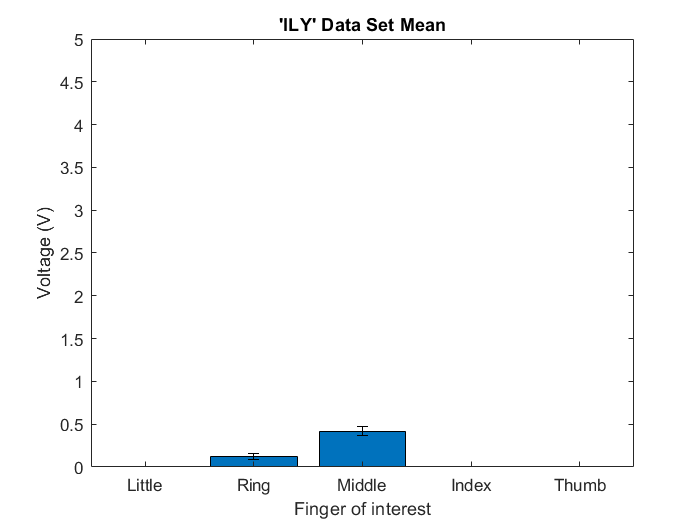



%ILY

ily0=readmatrix("FlexiAmSL.csv","Range","C122:C131");
ily1=readmatrix("FlexiAmSL.csv","Range","D122:D131");
ily2=readmatrix("FlexiAmSL.csv","Range","E122:E131");
ily3=readmatrix("FlexiAmSL.csv","Range","F122:F131");
ily4=readmatrix("FlexiAmSL.csv","Range","G122:G131");
ily5=[mean(ily0),mean(ily1),mean(ily2),mean(ily3),mean(ily4)];
ilyerr=[std(ily0),std(ily1),std(ily2),std(ily3),std(ily4)];
bar(names,ily5)
hold on
er=errorbar(names,ily5,ilyerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''ILY'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

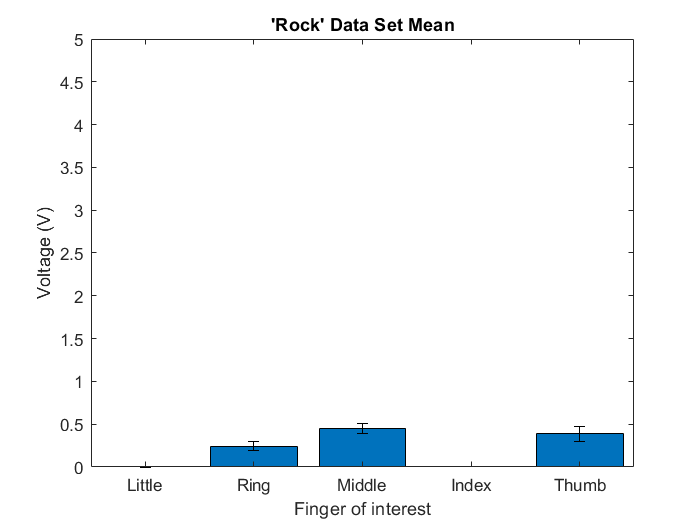



%Rock

rock0=readmatrix("FlexiAmSL.csv","Range","C132:C141");
rock1=readmatrix("FlexiAmSL.csv","Range","D132:D141");
rock2=readmatrix("FlexiAmSL.csv","Range","E132:E141");
rock3=readmatrix("FlexiAmSL.csv","Range","F132:F141");
rock4=readmatrix("FlexiAmSL.csv","Range","G132:G141");
rock5=[mean(rock0),mean(rock1),mean(rock2),mean(rock3),mean(rock4)];
rockerr=[std(rock0),std(rock1),std(rock2),std(rock3),std(rock4)];
bar(names,rock5)
hold on
er=errorbar(names,rock5,rockerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Rock'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

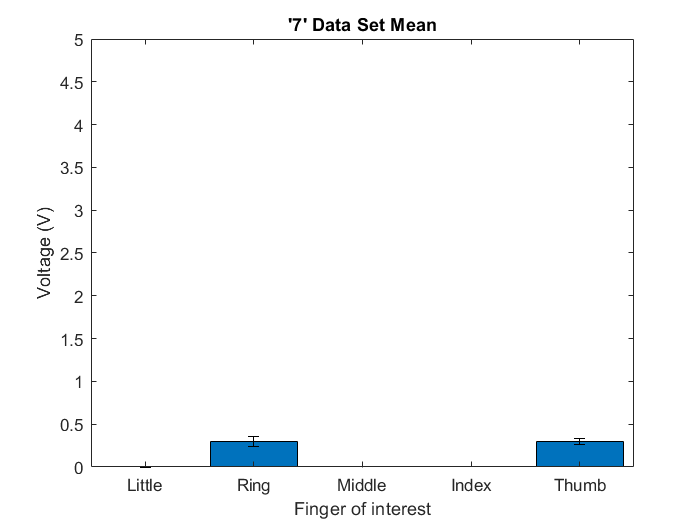



%7

sev0=readmatrix("FlexiAmSL.csv","Range","C142:C151");
sev1=readmatrix("FlexiAmSL.csv","Range","D142:D151");
sev2=readmatrix("FlexiAmSL.csv","Range","E142:E151");
sev3=readmatrix("FlexiAmSL.csv","Range","F142:F151");
sev4=readmatrix("FlexiAmSL.csv","Range","G142:G151");
sev5=[mean(sev0),mean(sev1),mean(sev2),mean(sev3),mean(sev4)];
severr=[std(sev0),std(sev1),std(sev2),std(sev3),std(sev4)];
bar(names,sev5)
hold on
er=errorbar(names,sev5,severr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''7'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

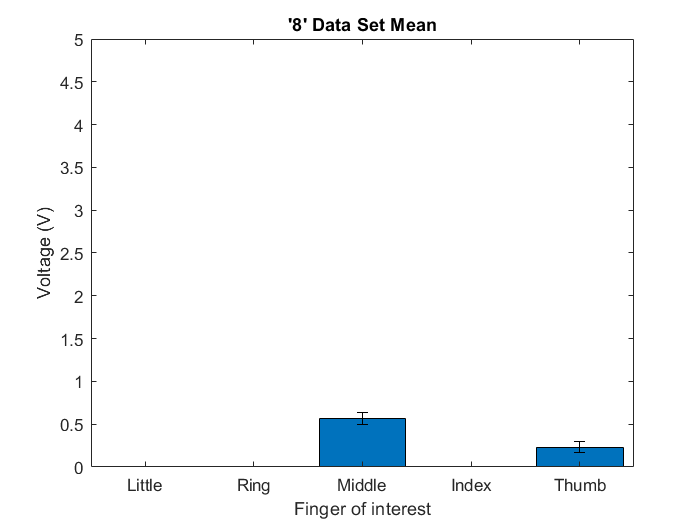



%8

eig0=readmatrix("FlexiAmSL.csv","Range","C152:C161");
eig1=readmatrix("FlexiAmSL.csv","Range","D152:D161");
eig2=readmatrix("FlexiAmSL.csv","Range","E152:E161");
eig3=readmatrix("FlexiAmSL.csv","Range","F152:F161");
eig4=readmatrix("FlexiAmSL.csv","Range","G152:G161");
eig5=[mean(eig0),mean(eig1),mean(eig2),mean(eig3),mean(eig4)];
eigerr=[std(eig0),std(eig1),std(eig2),std(eig3),std(eig4)];
bar(names,eig5)
hold on
er=errorbar(names,eig5,eigerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''8'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

## Foam SNR Tests

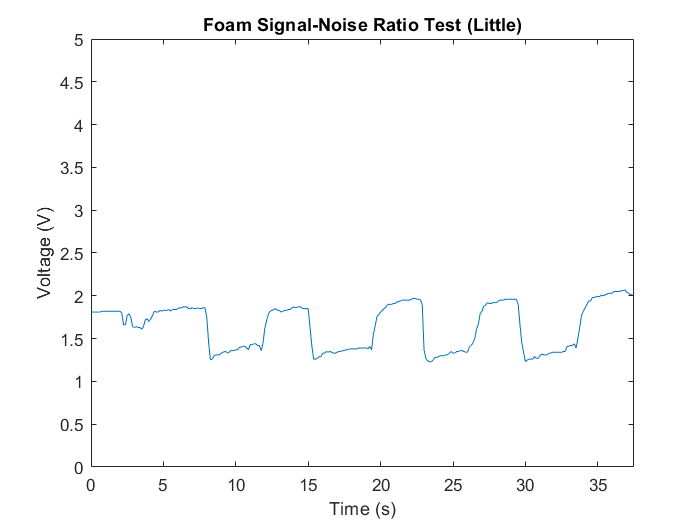

snr=0:1/8:299/8;
snr0=readmatrix("ReproData.csv","Range","A3:KN3");
snr1=readmatrix("ReproData.csv","Range","A5:KN5");
snr2=readmatrix("ReproData.csv","Range","A7:KN7");
snr3=readmatrix("ReproData.csv","Range","A9:KN9");
snr4=readmatrix("ReproData.csv","Range","A11:KN11");


plot(snr,snr0)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Foam Signal-Noise Ratio Test (Little)')
ylim([0 5]);
xlim([0 37.5])

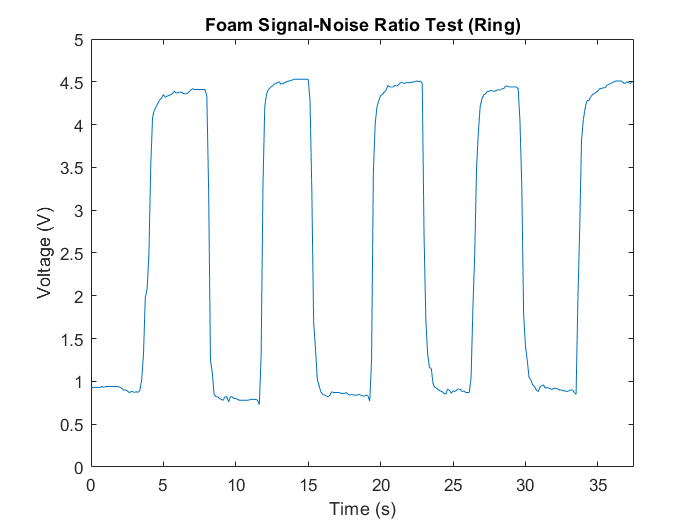


plot(snr,snr1)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Foam Signal-Noise Ratio Test (Ring)')
ylim([0 5]);
xlim([0 37.5])

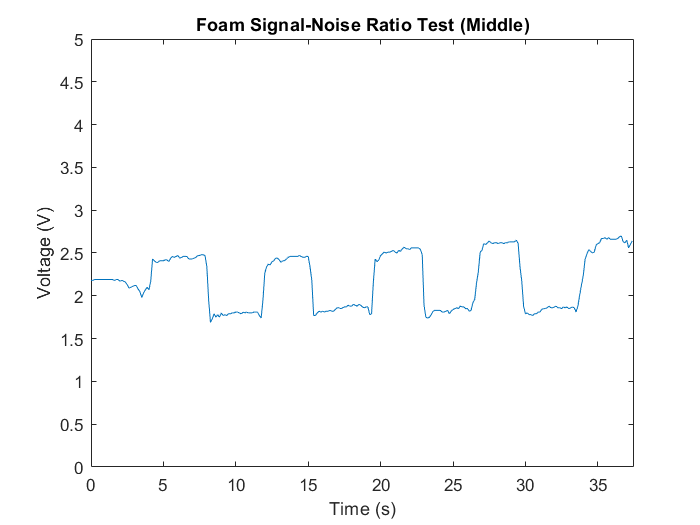


plot(snr,snr2)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Foam Signal-Noise Ratio Test (Middle)')
ylim([0 5]);
xlim([0 37.5])

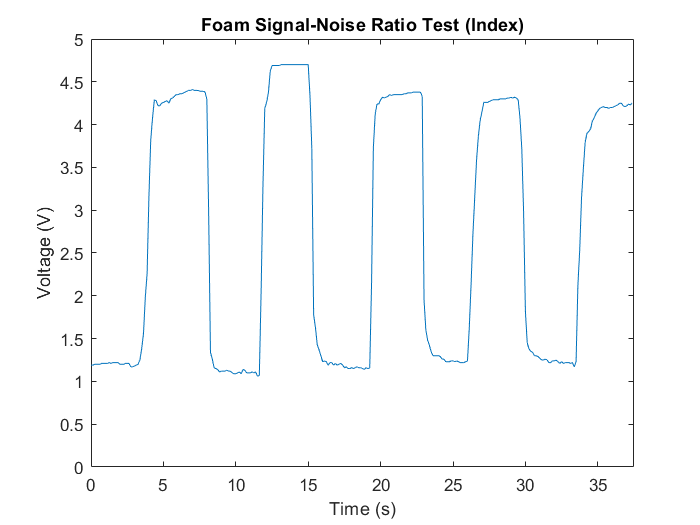


plot(snr,snr3)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Foam Signal-Noise Ratio Test (Index)')
ylim([0 5]);
xlim([0 37.5])

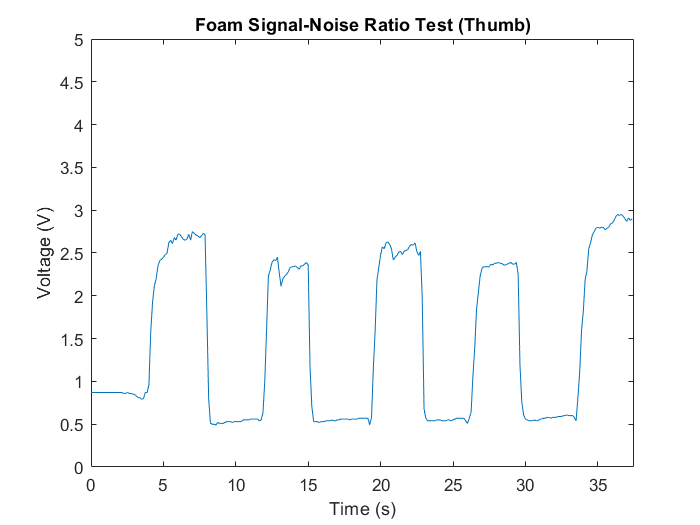


plot(snr,snr4)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Foam Signal-Noise Ratio Test (Thumb)')
ylim([0 5]);
xlim([0 37.5])

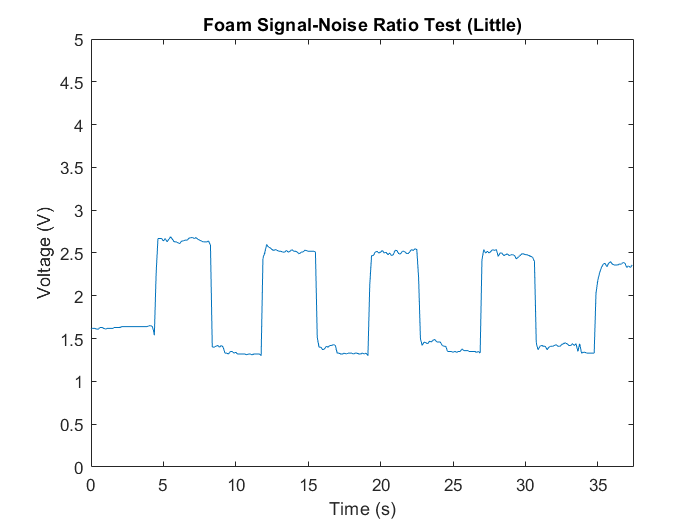


snr0redo=readmatrix("PinkyTest.csv","Range","A15:KN15");
plot(snr,snr0redo)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Foam Signal-Noise Ratio Test (Little)')
ylim([0 5]);
xlim([0 37.5])

## FlexiForce SNR Tests

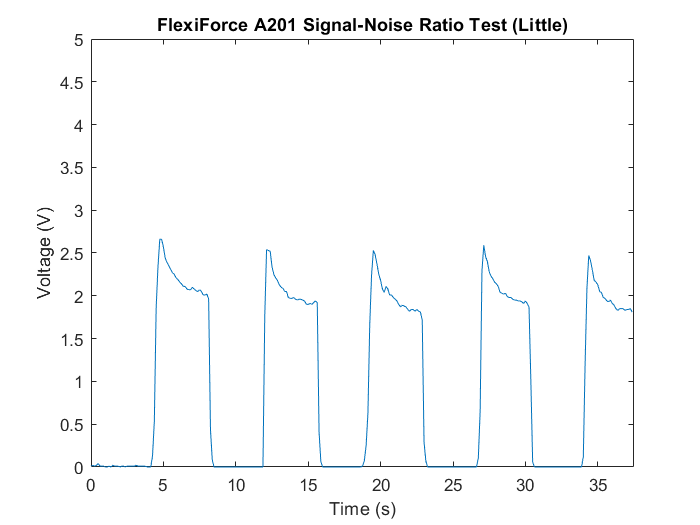

fsnr=0:1/8:299/8;
fsnr0=readmatrix("FlexiSNR.csv","Range","A3:KN3");
fsnr1=readmatrix("FlexiSNR.csv","Range","A5:KN5");
fsnr2=readmatrix("FlexiSNR.csv","Range","A7:KN7");
fsnr3=readmatrix("FlexiSNR.csv","Range","A9:KN9");
fsnr4=readmatrix("FlexiSNR.csv","Range","A11:KN11");


plot(fsnr,fsnr0)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('FlexiForce A201 Signal-Noise Ratio Test (Little)')
ylim([0 5])
xlim([0 37.5])

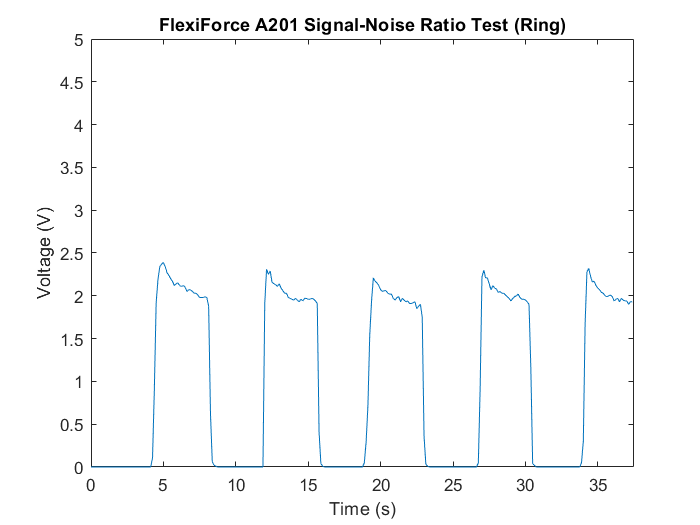


plot(fsnr,fsnr1)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('FlexiForce A201 Signal-Noise Ratio Test (Ring)')
ylim([0 5])
xlim([0 37.5])

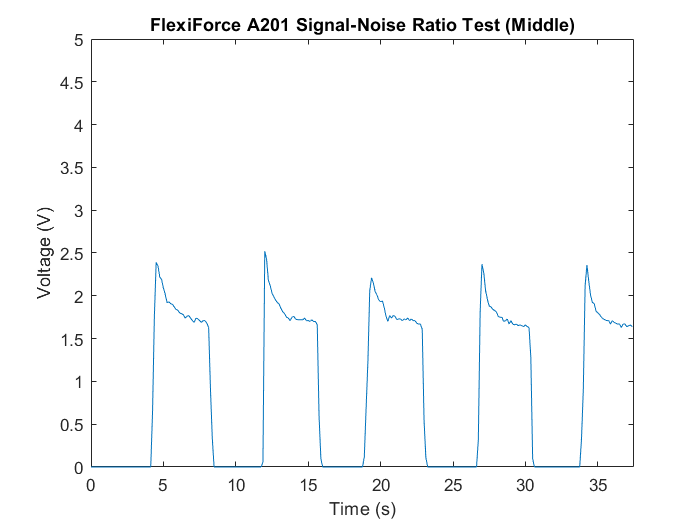


plot(fsnr,fsnr2)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('FlexiForce A201 Signal-Noise Ratio Test (Middle)')
ylim([0 5])
xlim([0 37.5])

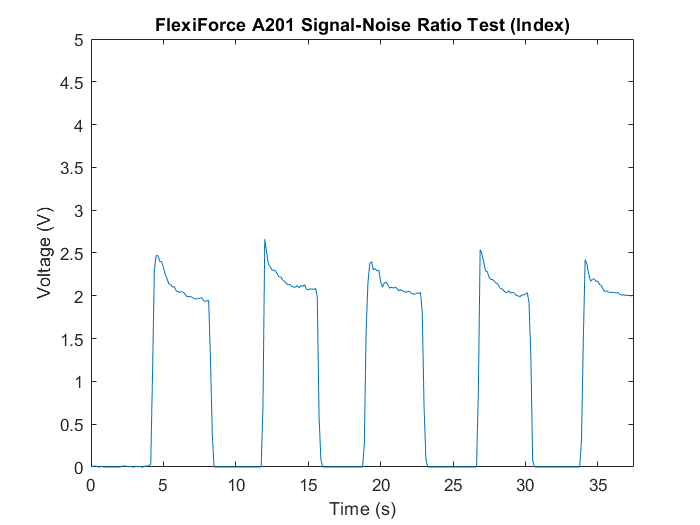


plot(fsnr,fsnr3)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('FlexiForce A201 Signal-Noise Ratio Test (Index)')
ylim([0 5])
xlim([0 37.5])

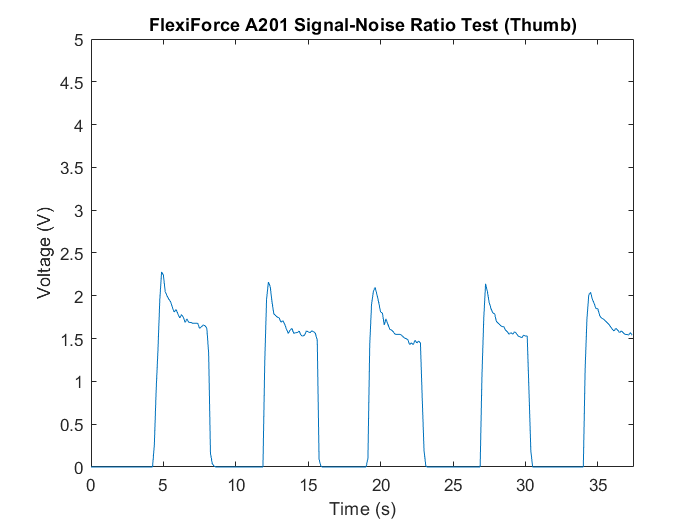


plot(fsnr,fsnr4)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('FlexiForce A201 Signal-Noise Ratio Test (Thumb)')
ylim([0 5])
xlim([0 37.5])

## Tensile Tests

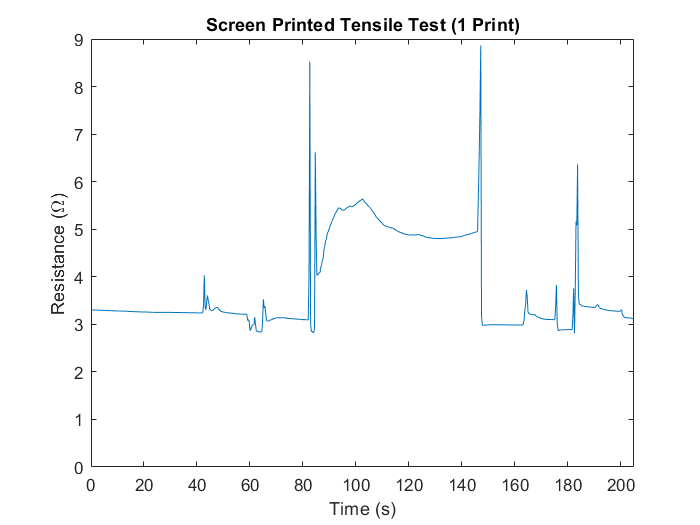

tt1=readmatrix("tenstest1passfinal.xlsx","Range","B1:B750");
tt1time=readmatrix("tenstest1passfinal.xlsx","Range","A1:A750");
%815
tt2=readmatrix("tenstest2passfinal.xlsx","Range","B1:B310");
tt2time=readmatrix("tenstest2passfinal.xlsx","Range","A1:A310");
tt3=readmatrix("tenstest3passfinal.xlsx","Range","B1:B1558");
tt3time=readmatrix("tenstest3passfinal.xlsx","Range","A1:A1558");
t3=readmatrix("tenstest3passfinal.xlsx","Range","B1:B900");
t3t=readmatrix("tenstest3passfinal.xlsx","Range","A1:A900");
plot(tt1time,tt1)
xlim([0 205])
ylim([0 9])
xlabel('Time (s)')
ylabel('Resistance (\Omega)')
title('Screen Printed Tensile Test (1 Print)')

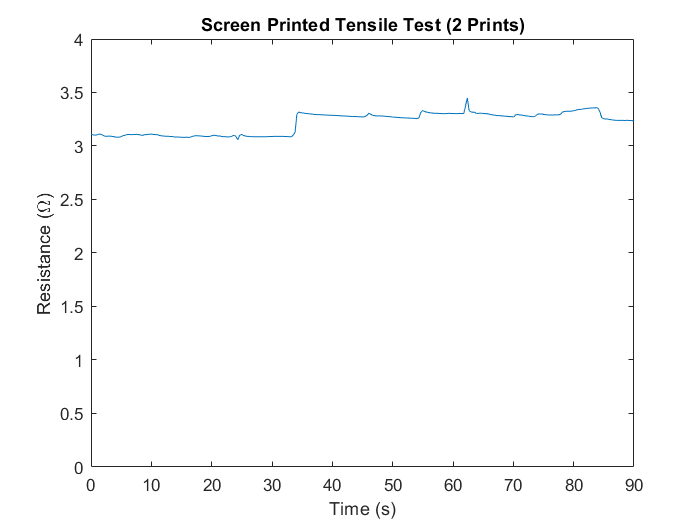

plot(tt2time,tt2)
xlim([0 90])
ylim([0 4])
xlabel('Time (s)')
ylabel('Resistance (\Omega)')
title('Screen Printed Tensile Test (2 Prints)')

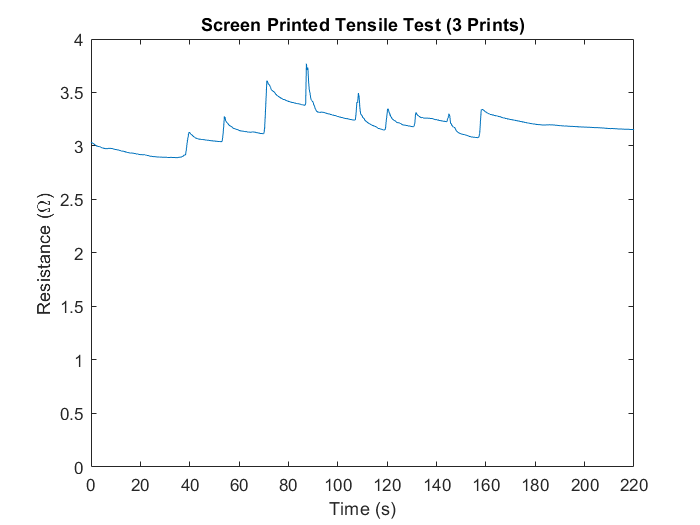

%plot(tt3time,tt3)
plot(t3t,t3)
xlim([0 220])
ylim([0 4])
xlabel('Time (s)')
ylabel('Resistance (\Omega)')
title('Screen Printed Tensile Test (3 Prints)')

## Bar Charts for each signal (FoamArSL)

%Baseline

b0=readmatrix("FoamArSL.csv","Range","C2:C11");
b1=readmatrix("FoamArSL.csv","Range","D2:D11");
b2=readmatrix("FoamArSL.csv","Range","E2:E11");
b3=readmatrix("FoamArSL.csv","Range","F2:F11");
b4=readmatrix("FoamArSL.csv","Range","G2:G11");
b5=[mean(b0),mean(b1),mean(b2),mean(b3),mean(b4)];
berr=[std(b0),std(b1),std(b2),std(b3),std(b4)];
bar(names,b5)
hold on
er=errorbar(names,b5,berr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Baseline'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

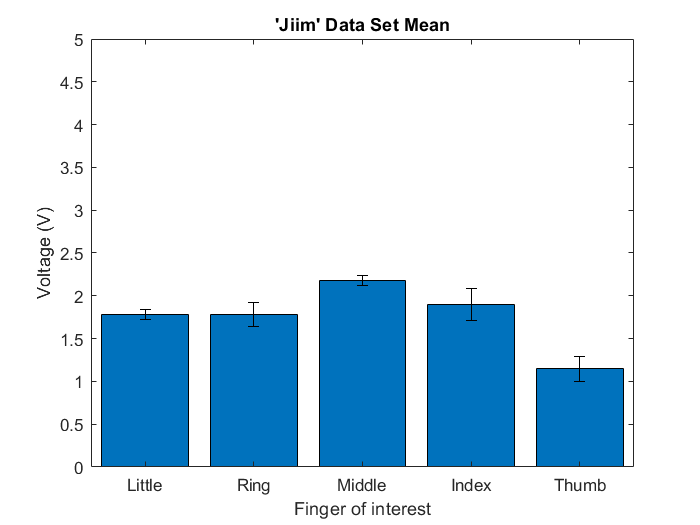


%1
one0=readmatrix("FoamArSL.csv","Range","C12:C21");
one1=readmatrix("FoamArSL.csv","Range","D12:D21");
one2=readmatrix("FoamArSL.csv","Range","E12:E21");
one3=readmatrix("FoamArSL.csv","Range","F12:F21");
one4=readmatrix("FoamArSL.csv","Range","G12:G21");
one5=[mean(one0),mean(one1),mean(one2),mean(one3),mean(one4)];
oneerr=[std(one0),std(one1),std(one2),std(one3),std(one4)];
bar(names,one5)
hold on
er=errorbar(names,one5,oneerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Jiim'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

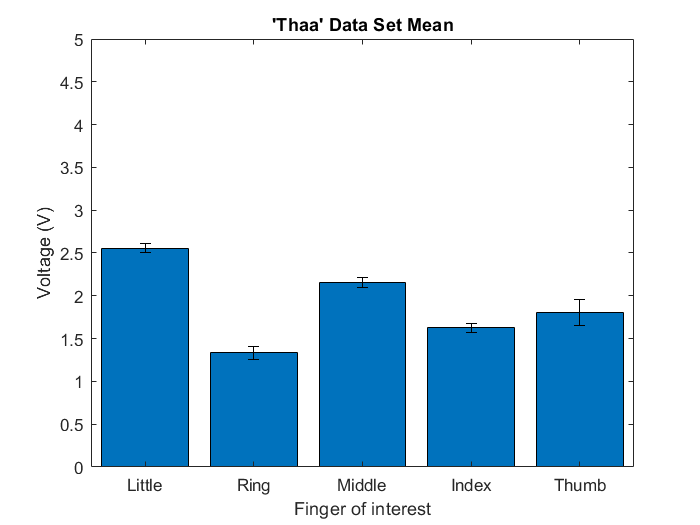



%2

two0=readmatrix("FoamArSL.csv","Range","C22:C31");
two1=readmatrix("FoamArSL.csv","Range","D22:D31");
two2=readmatrix("FoamArSL.csv","Range","E22:E31");
two3=readmatrix("FoamArSL.csv","Range","F22:F31");
two4=readmatrix("FoamArSL.csv","Range","G22:G31");
two5=[mean(two0),mean(two1),mean(two2),mean(two3),mean(two4)];
twoerr=[std(two0),std(two1),std(two2),std(two3),std(two4)];
bar(names,two5)
hold on
er=errorbar(names,two5,twoerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Thaa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

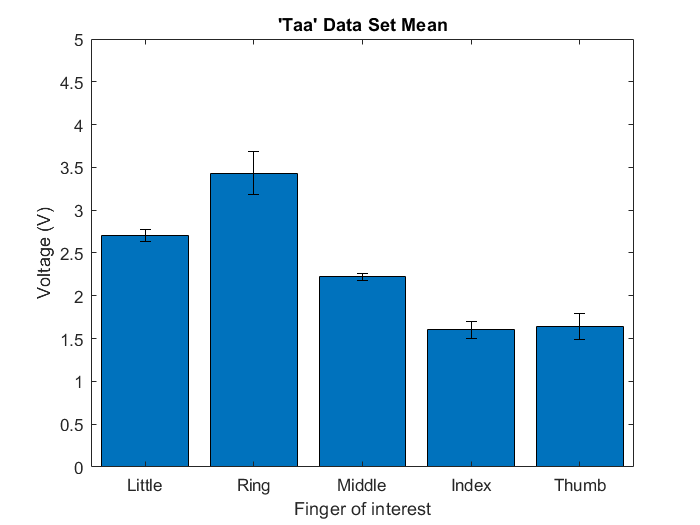



%3

thr0=readmatrix("FoamArSL.csv","Range","C32:C41");
thr1=readmatrix("FoamArSL.csv","Range","D32:D41");
thr2=readmatrix("FoamArSL.csv","Range","E32:E41");
thr3=readmatrix("FoamArSL.csv","Range","F32:F41");
thr4=readmatrix("FoamArSL.csv","Range","G32:G41");
thr5=[mean(thr0),mean(thr1),mean(thr2),mean(thr3),mean(thr4)];
threrr=[std(thr0),std(thr1),std(thr2),std(thr3),std(thr4)];
bar(names,thr5)
hold on
er=errorbar(names,thr5,threrr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Taa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

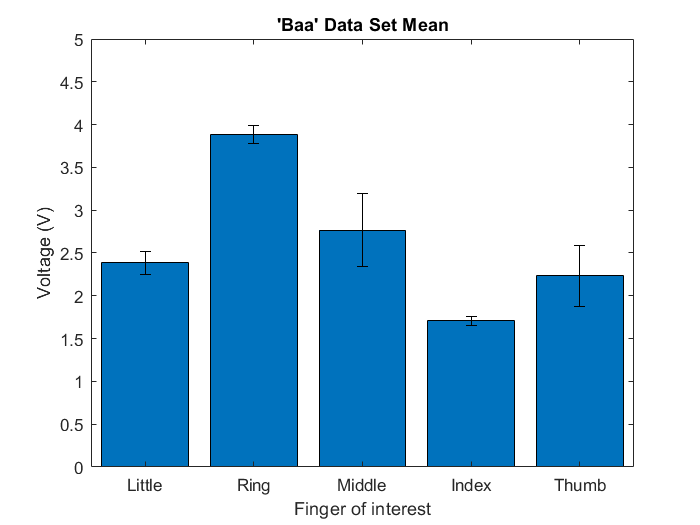



%4

four0=readmatrix("FoamArSL.csv","Range","C42:C51");
four1=readmatrix("FoamArSL.csv","Range","D42:D51");
four2=readmatrix("FoamArSL.csv","Range","E42:E51");
four3=readmatrix("FoamArSL.csv","Range","F42:F51");
four4=readmatrix("FoamArSL.csv","Range","G42:G51");
four5=[mean(four0),mean(four1),mean(four2),mean(four3),mean(four4)];
fourerr=[std(four0),std(four1),std(four2),std(four3),std(four4)];
bar(names,four5)
hold on
er=errorbar(names,four5,fourerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Baa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

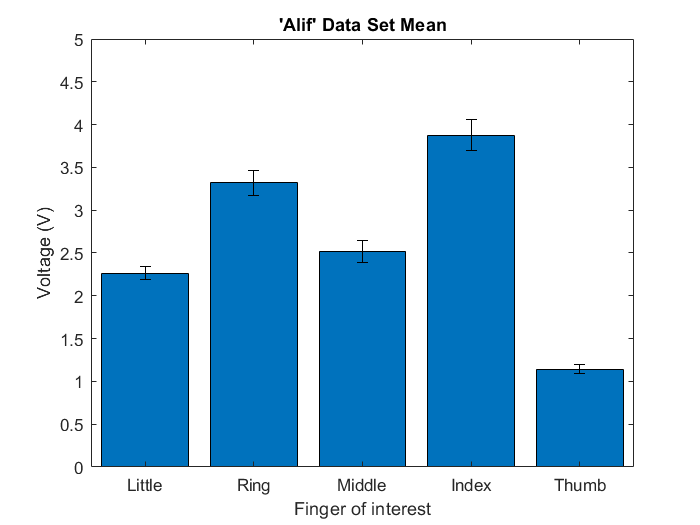



%A

a0=readmatrix("FoamArSL.csv","Range","C52:C61");
a1=readmatrix("FoamArSL.csv","Range","D52:D61");
a2=readmatrix("FoamArSL.csv","Range","E52:E61");
a3=readmatrix("FoamArSL.csv","Range","F52:F61");
a4=readmatrix("FoamArSL.csv","Range","G52:G61");
a5=[mean(a0),mean(a1),mean(a2),mean(a3),mean(a4)];
aerr=[std(a0),std(a1),std(a2),std(a3),std(a4)];
bar(names,a5)
hold on
er=errorbar(names,a5,aerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Alif'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

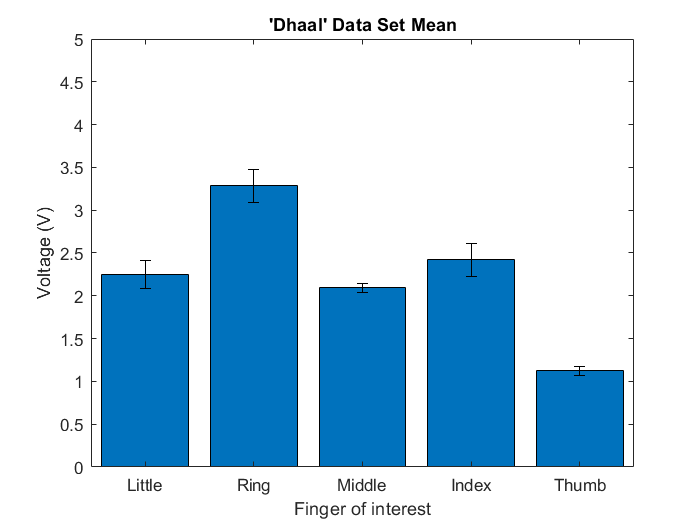



%F

f0=readmatrix("FoamArSL.csv","Range","C62:C71");
f1=readmatrix("FoamArSL.csv","Range","D62:D71");
f2=readmatrix("FoamArSL.csv","Range","E62:E71");
f3=readmatrix("FoamArSL.csv","Range","F62:F71");
f4=readmatrix("FoamArSL.csv","Range","G62:G71");
f5=[mean(f0),mean(f1),mean(f2),mean(f3),mean(f4)];
ferr=[std(f0),std(f1),std(f2),std(f3),std(f4)];
bar(names,f5)
hold on
er=errorbar(names,f5,ferr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Dhaal'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

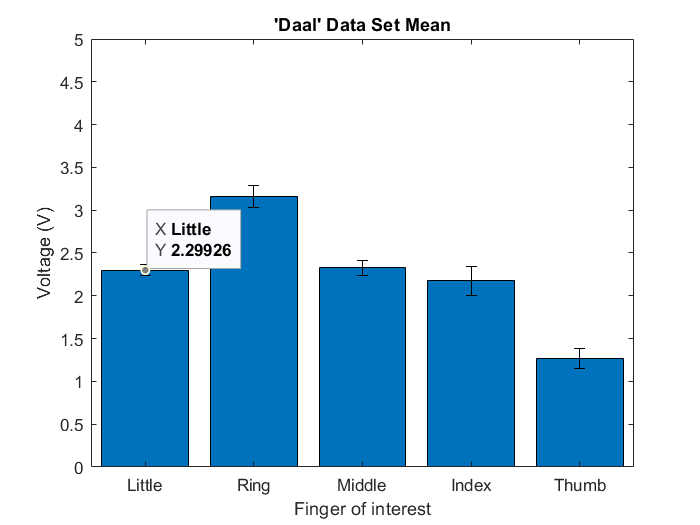



%I

i0=readmatrix("FoamArSL.csv","Range","C72:C81");
i1=readmatrix("FoamArSL.csv","Range","D72:D81");
i2=readmatrix("FoamArSL.csv","Range","E72:E81");
i3=readmatrix("FoamArSL.csv","Range","F72:F81");
i4=readmatrix("FoamArSL.csv","Range","G72:G81");
i5=[mean(i0),mean(i1),mean(i2),mean(i3),mean(i4)];
ierr=[std(i0),std(i1),std(i2),std(i3),std(i4)];
bar(names,i5)
hold on
er=errorbar(names,i5,ierr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Daal'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

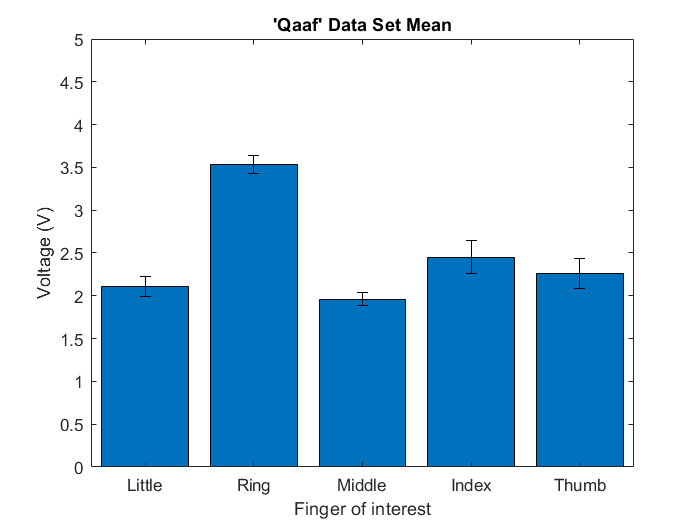



%L

l0=readmatrix("FoamArSL.csv","Range","C82:C91");
l1=readmatrix("FoamArSL.csv","Range","D82:D91");
l2=readmatrix("FoamArSL.csv","Range","E82:E91");
l3=readmatrix("FoamArSL.csv","Range","F82:F91");
l4=readmatrix("FoamArSL.csv","Range","G82:G91");
l5=[mean(l0),mean(l1),mean(l2),mean(l3),mean(l4)];
lerr=[std(l0),std(l1),std(l2),std(l3),std(l4)];
bar(names,l5)
hold on
er=errorbar(names,l5,lerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Qaaf'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

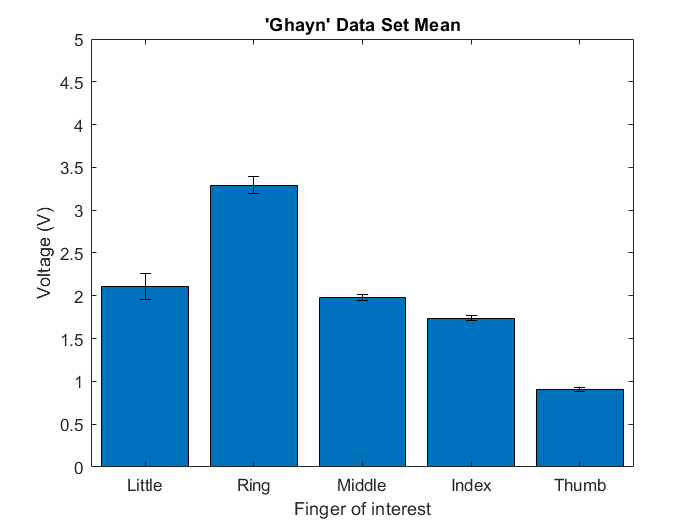



%s

s0=readmatrix("FoamArSL.csv","Range","C92:C101");
s1=readmatrix("FoamArSL.csv","Range","D92:D101");
s2=readmatrix("FoamArSL.csv","Range","E92:E101");
s3=readmatrix("FoamArSL.csv","Range","F92:F101");
s4=readmatrix("FoamArSL.csv","Range","G92:G101");
s5=[mean(s0),mean(s1),mean(s2),mean(s3),mean(s4)];
serr=[std(s0),std(s1),std(s2),std(s3),std(s4)];
bar(names,s5)
hold on
er=errorbar(names,s5,serr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Ghayn'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

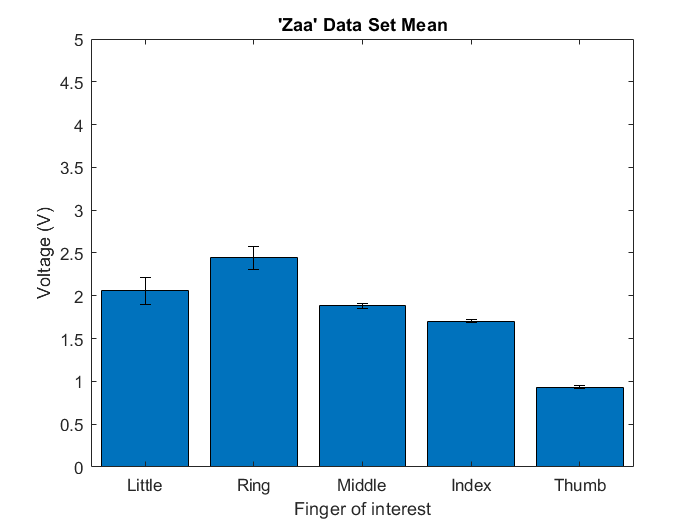



%W

w0=readmatrix("FoamArSL.csv","Range","C102:C111");
w1=readmatrix("FoamArSL.csv","Range","D102:D111");
w2=readmatrix("FoamArSL.csv","Range","E102:E111");
w3=readmatrix("FoamArSL.csv","Range","F102:F111");
w4=readmatrix("FoamArSL.csv","Range","G102:G111");
w5=[mean(w0),mean(w1),mean(w2),mean(w3),mean(w4)];
werr=[std(w0),std(w1),std(w2),std(w3),std(w4)];
bar(names,w5)
hold on
er=errorbar(names,w5,werr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Zaa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

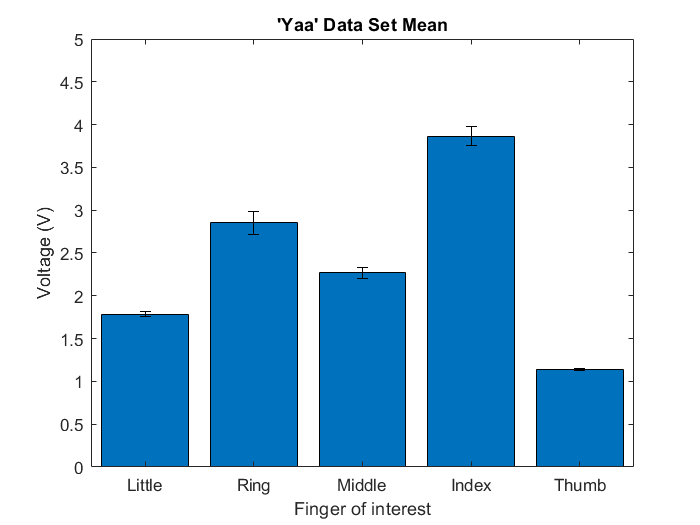



%Y

y0=readmatrix("FoamArSL.csv","Range","C112:C121");
y1=readmatrix("FoamArSL.csv","Range","D112:D121");
y2=readmatrix("FoamArSL.csv","Range","E112:E121");
y3=readmatrix("FoamArSL.csv","Range","F112:F121");
y4=readmatrix("FoamArSL.csv","Range","G112:G121");
y5=[mean(y0),mean(y1),mean(y2),mean(y3),mean(y4)];
yerr=[std(y0),std(y1),std(y2),std(y3),std(y4)];
bar(names,y5)
hold on
er=errorbar(names,y5,yerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Yaa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

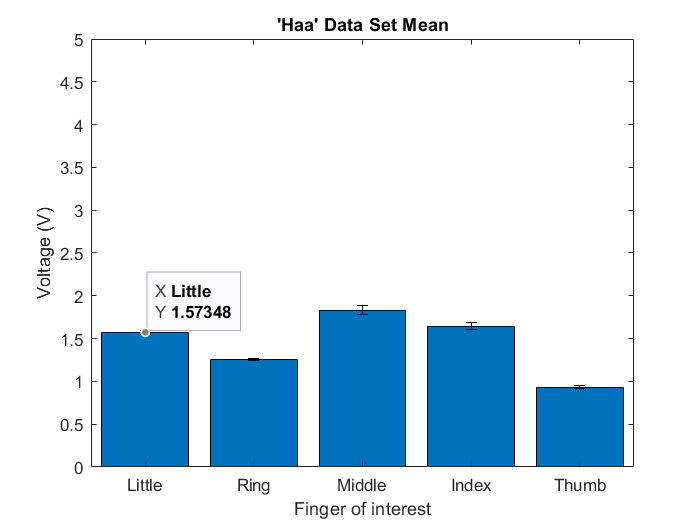



%ILY

ily0=readmatrix("FoamArSL.csv","Range","C122:C131");
ily1=readmatrix("FoamArSL.csv","Range","D122:D131");
ily2=readmatrix("FoamArSL.csv","Range","E122:E131");
ily3=readmatrix("FoamArSL.csv","Range","F122:F131");
ily4=readmatrix("FoamArSL.csv","Range","G122:G131");
ily5=[mean(ily0),mean(ily1),mean(ily2),mean(ily3),mean(ily4)];
ilyerr=[std(ily0),std(ily1),std(ily2),std(ily3),std(ily4)];
bar(names,ily5)
hold on
er=errorbar(names,ily5,ilyerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Haa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

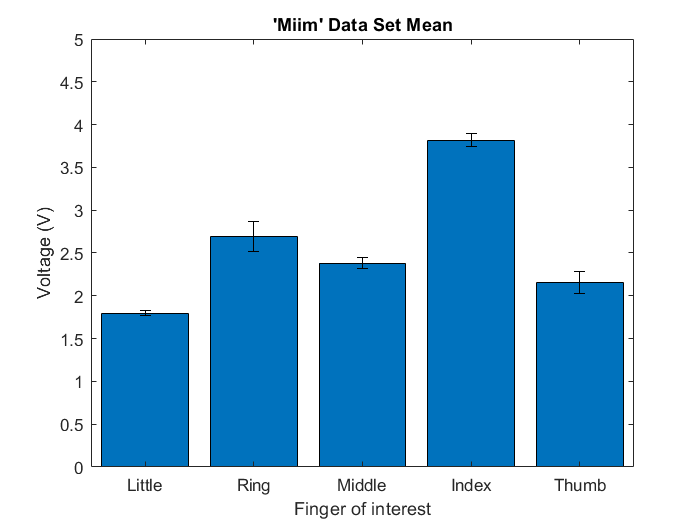



%Rock

rock0=readmatrix("FoamArSL.csv","Range","C132:C141");
rock1=readmatrix("FoamArSL.csv","Range","D132:D141");
rock2=readmatrix("FoamArSL.csv","Range","E132:E141");
rock3=readmatrix("FoamArSL.csv","Range","F132:F141");
rock4=readmatrix("FoamArSL.csv","Range","G132:G141");
rock5=[mean(rock0),mean(rock1),mean(rock2),mean(rock3),mean(rock4)];
rockerr=[std(rock0),std(rock1),std(rock2),std(rock3),std(rock4)];
bar(names,rock5)
hold on
er=errorbar(names,rock5,rockerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Miim'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

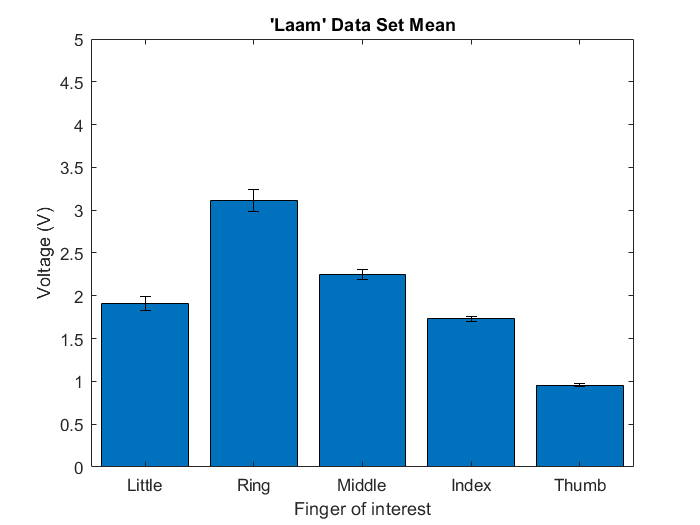



%7

sev0=readmatrix("FoamArSL.csv","Range","C142:C151");
sev1=readmatrix("FoamArSL.csv","Range","D142:D151");
sev2=readmatrix("FoamArSL.csv","Range","E142:E151");
sev3=readmatrix("FoamArSL.csv","Range","F142:F151");
sev4=readmatrix("FoamArSL.csv","Range","G142:G151");
sev5=[mean(sev0),mean(sev1),mean(sev2),mean(sev3),mean(sev4)];
severr=[std(sev0),std(sev1),std(sev2),std(sev3),std(sev4)];
bar(names,sev5)
hold on
er=errorbar(names,sev5,severr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Laam'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

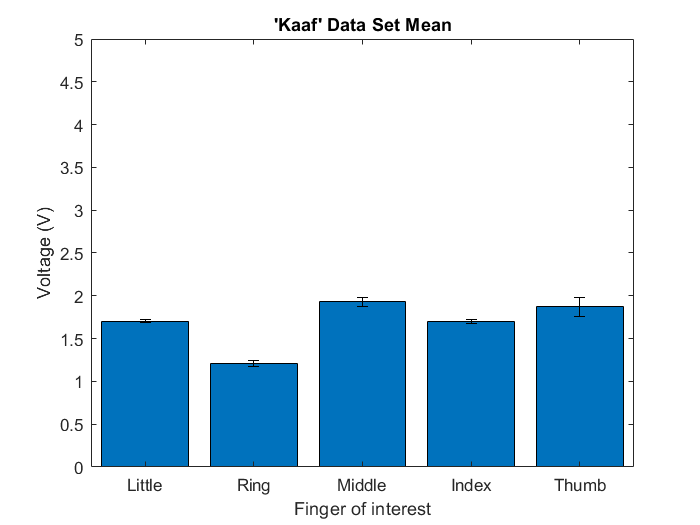



%8

eig0=readmatrix("FoamArSL.csv","Range","C152:C161");
eig1=readmatrix("FoamArSL.csv","Range","D152:D161");
eig2=readmatrix("FoamArSL.csv","Range","E152:E161");
eig3=readmatrix("FoamArSL.csv","Range","F152:F161");
eig4=readmatrix("FoamArSL.csv","Range","G152:G161");
eig5=[mean(eig0),mean(eig1),mean(eig2),mean(eig3),mean(eig4)];
eigerr=[std(eig0),std(eig1),std(eig2),std(eig3),std(eig4)];
bar(names,eig5)
hold on
er=errorbar(names,eig5,eigerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Kaaf'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

## Bar Charts for each signal (FlexiArSL)

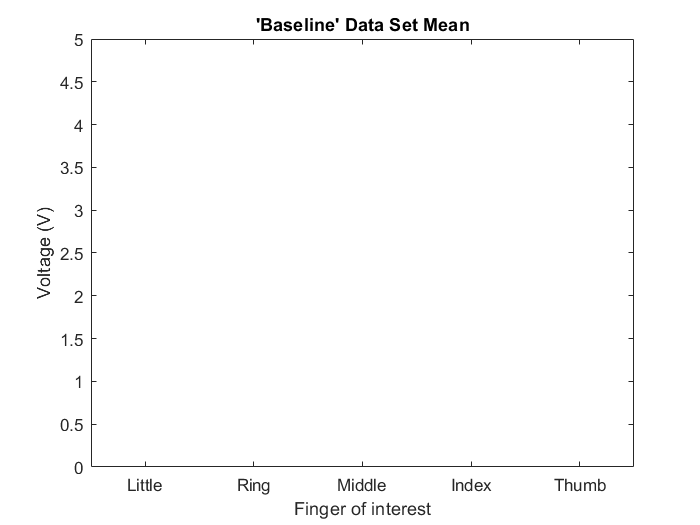

%Baseline
b0=readmatrix("FlexiArSL.csv","Range","C2:C11");
b1=readmatrix("FlexiArSL.csv","Range","D2:D11");
b2=readmatrix("FlexiArSL.csv","Range","E2:E11");
b3=readmatrix("FlexiArSL.csv","Range","F2:F11");
b4=readmatrix("FlexiArSL.csv","Range","G2:G11");
b5=[mean(b0),mean(b1),mean(b2),mean(b3),mean(b4)];
berr=[std(b0),std(b1),std(b2),std(b3),std(b4)];
bar(names,b5)
hold on
er=errorbar(names,b5,berr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Baseline'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

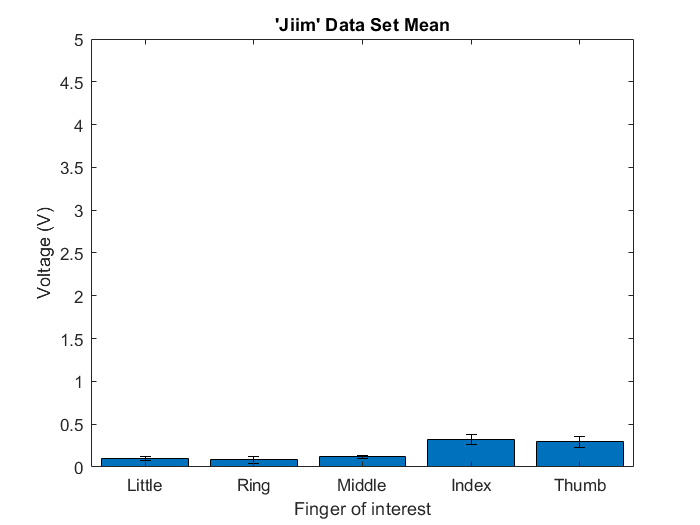


%1
one0=readmatrix("FlexiArSL.csv","Range","C12:C21");
one1=readmatrix("FlexiArSL.csv","Range","D12:D21");
one2=readmatrix("FlexiArSL.csv","Range","E12:E21");
one3=readmatrix("FlexiArSL.csv","Range","F12:F21");
one4=readmatrix("FlexiArSL.csv","Range","G12:G21");
one5=[mean(one0),mean(one1),mean(one2),mean(one3),mean(one4)];
oneerr=[std(one0),std(one1),std(one2),std(one3),std(one4)];
bar(names,one5)
hold on
er=errorbar(names,one5,oneerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Jiim'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

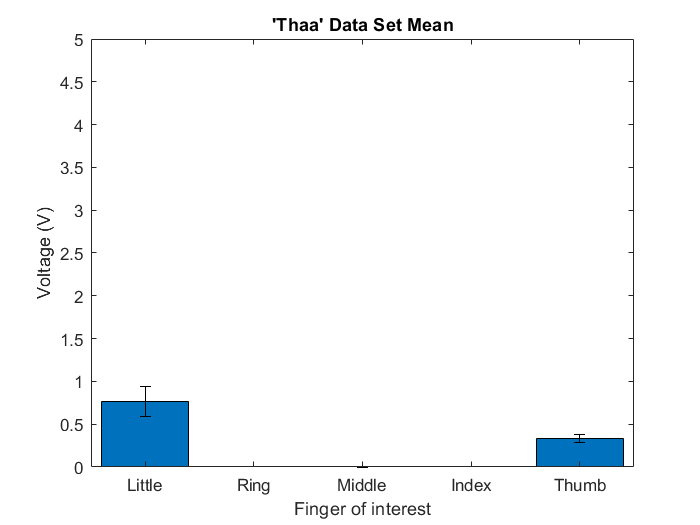



%2

two0=readmatrix("FlexiArSL.csv","Range","C22:C31");
two1=readmatrix("FlexiArSL.csv","Range","D22:D31");
two2=readmatrix("FlexiArSL.csv","Range","E22:E31");
two3=readmatrix("FlexiArSL.csv","Range","F22:F31");
two4=readmatrix("FlexiArSL.csv","Range","G22:G31");
two5=[mean(two0),mean(two1),mean(two2),mean(two3),mean(two4)];
twoerr=[std(two0),std(two1),std(two2),std(two3),std(two4)];
bar(names,two5)
hold on
er=errorbar(names,two5,twoerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Thaa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

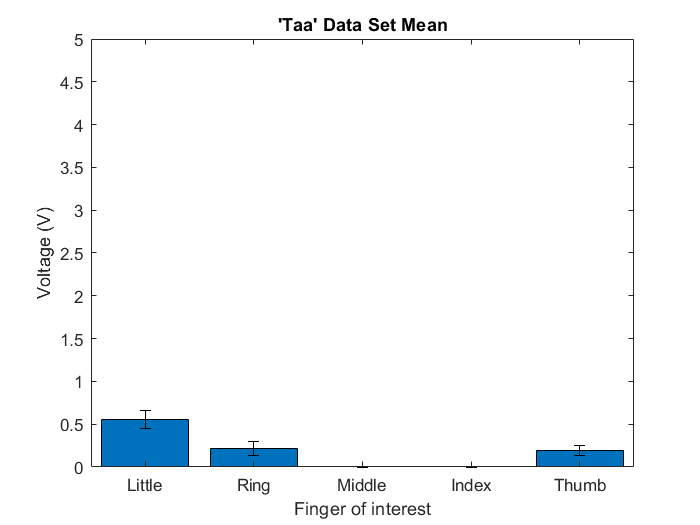



%3

thr0=readmatrix("FlexiArSL.csv","Range","C32:C41");
thr1=readmatrix("FlexiArSL.csv","Range","D32:D41");
thr2=readmatrix("FlexiArSL.csv","Range","E32:E41");
thr3=readmatrix("FlexiArSL.csv","Range","F32:F41");
thr4=readmatrix("FlexiArSL.csv","Range","G32:G41");
thr5=[mean(thr0),mean(thr1),mean(thr2),mean(thr3),mean(thr4)];
threrr=[std(thr0),std(thr1),std(thr2),std(thr3),std(thr4)];
bar(names,thr5)
hold on
er=errorbar(names,thr5,threrr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Taa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

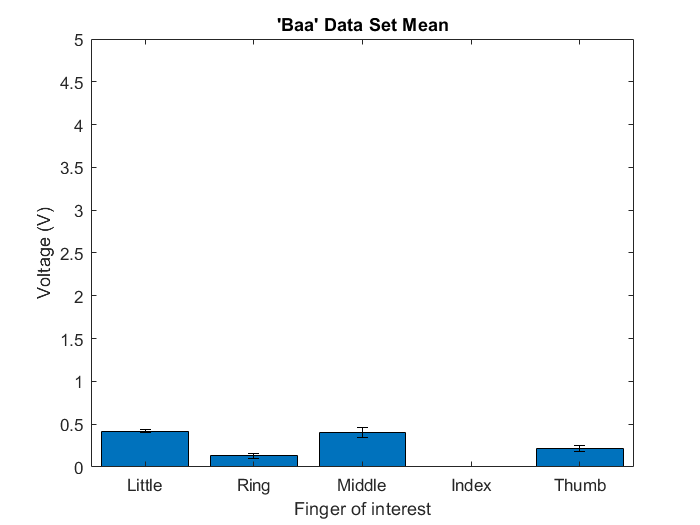



%4

four0=readmatrix("FlexiArSL.csv","Range","C42:C51");
four1=readmatrix("FlexiArSL.csv","Range","D42:D51");
four2=readmatrix("FlexiArSL.csv","Range","E42:E51");
four3=readmatrix("FlexiArSL.csv","Range","F42:F51");
four4=readmatrix("FlexiArSL.csv","Range","G42:G51");
four5=[mean(four0),mean(four1),mean(four2),mean(four3),mean(four4)];
fourerr=[std(four0),std(four1),std(four2),std(four3),std(four4)];
bar(names,four5)
hold on
er=errorbar(names,four5,fourerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Baa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

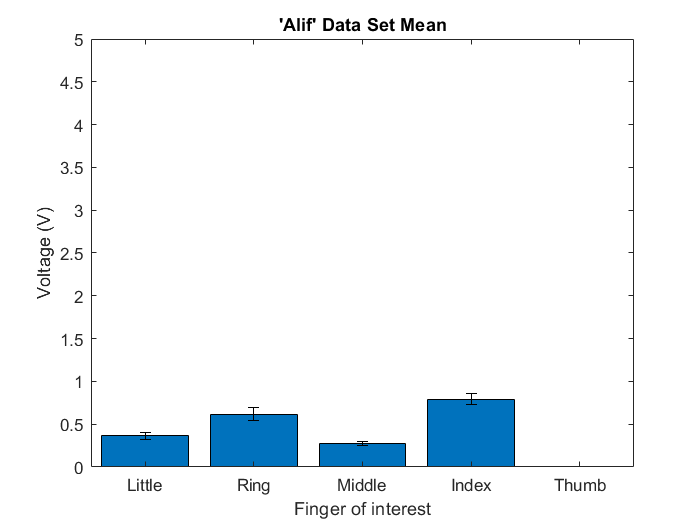



%A

a0=readmatrix("FlexiArSL.csv","Range","C52:C61");
a1=readmatrix("FlexiArSL.csv","Range","D52:D61");
a2=readmatrix("FlexiArSL.csv","Range","E52:E61");
a3=readmatrix("FlexiArSL.csv","Range","F52:F61");
a4=readmatrix("FlexiArSL.csv","Range","G52:G61");
a5=[mean(a0),mean(a1),mean(a2),mean(a3),mean(a4)];
aerr=[std(a0),std(a1),std(a2),std(a3),std(a4)];
bar(names,a5)
hold on
er=errorbar(names,a5,aerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Alif'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

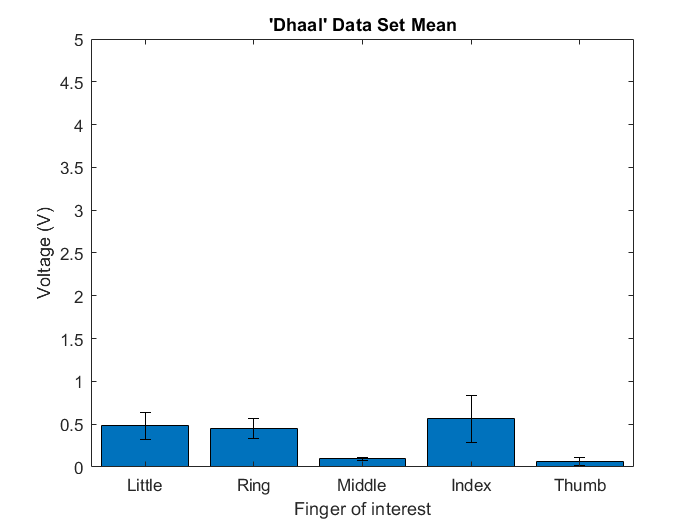



%F

f0=readmatrix("FlexiArSL.csv","Range","C62:C71");
f1=readmatrix("FlexiArSL.csv","Range","D62:D71");
f2=readmatrix("FlexiArSL.csv","Range","E62:E71");
f3=readmatrix("FlexiArSL.csv","Range","F62:F71");
f4=readmatrix("FlexiArSL.csv","Range","G62:G71");
f5=[mean(f0),mean(f1),mean(f2),mean(f3),mean(f4)];
ferr=[std(f0),std(f1),std(f2),std(f3),std(f4)];
bar(names,f5)
hold on
er=errorbar(names,f5,ferr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Dhaal'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

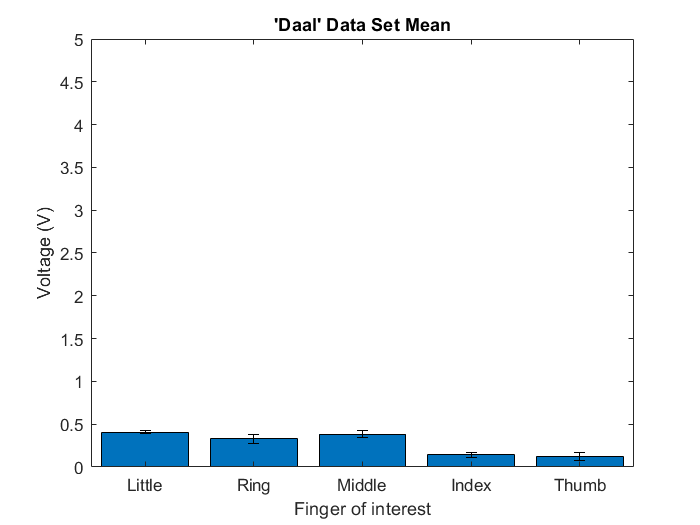



%I

i0=readmatrix("FlexiArSL.csv","Range","C72:C81");
i1=readmatrix("FlexiArSL.csv","Range","D72:D81");
i2=readmatrix("FlexiArSL.csv","Range","E72:E81");
i3=readmatrix("FlexiArSL.csv","Range","F72:F81");
i4=readmatrix("FlexiArSL.csv","Range","G72:G81");
i5=[mean(i0),mean(i1),mean(i2),mean(i3),mean(i4)];
ierr=[std(i0),std(i1),std(i2),std(i3),std(i4)];
bar(names,i5)
hold on
er=errorbar(names,i5,ierr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Daal'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

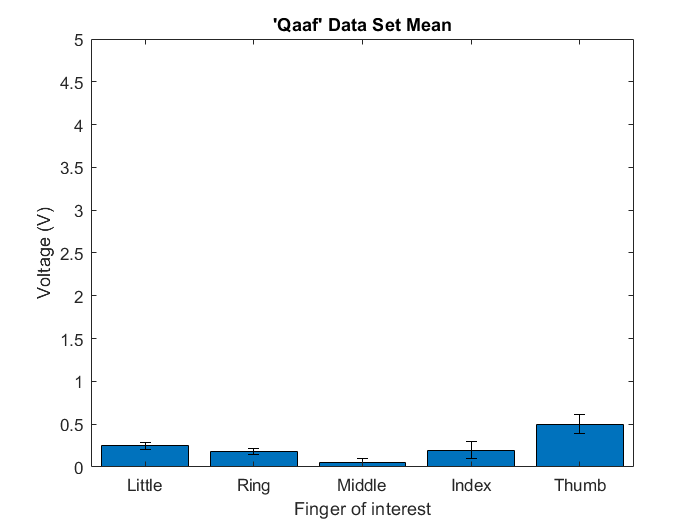



%L

l0=readmatrix("FlexiArSL.csv","Range","C82:C91");
l1=readmatrix("FlexiArSL.csv","Range","D82:D91");
l2=readmatrix("FlexiArSL.csv","Range","E82:E91");
l3=readmatrix("FlexiArSL.csv","Range","F82:F91");
l4=readmatrix("FlexiArSL.csv","Range","G82:G91");
l5=[mean(l0),mean(l1),mean(l2),mean(l3),mean(l4)];
lerr=[std(l0),std(l1),std(l2),std(l3),std(l4)];
bar(names,l5)
hold on
er=errorbar(names,l5,lerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Qaaf'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

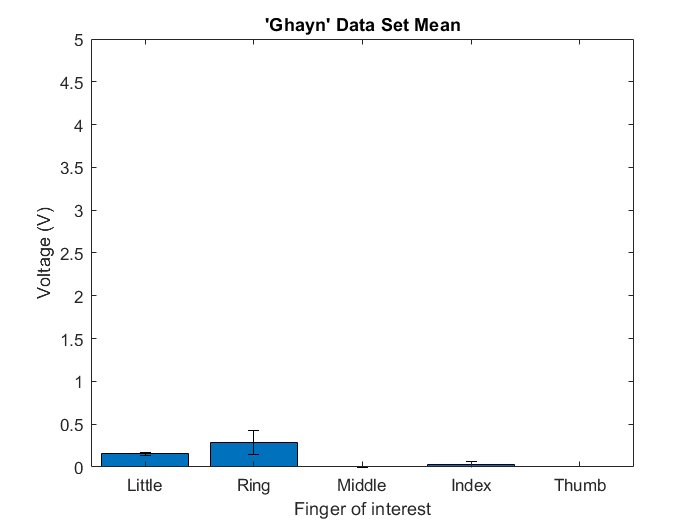



%s

s0=readmatrix("FlexiArSL.csv","Range","C92:C101");
s1=readmatrix("FlexiArSL.csv","Range","D92:D101");
s2=readmatrix("FlexiArSL.csv","Range","E92:E101");
s3=readmatrix("FlexiArSL.csv","Range","F92:F101");
s4=readmatrix("FlexiArSL.csv","Range","G92:G101");
s5=[mean(s0),mean(s1),mean(s2),mean(s3),mean(s4)];
serr=[std(s0),std(s1),std(s2),std(s3),std(s4)];
bar(names,s5)
hold on
er=errorbar(names,s5,serr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Ghayn'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

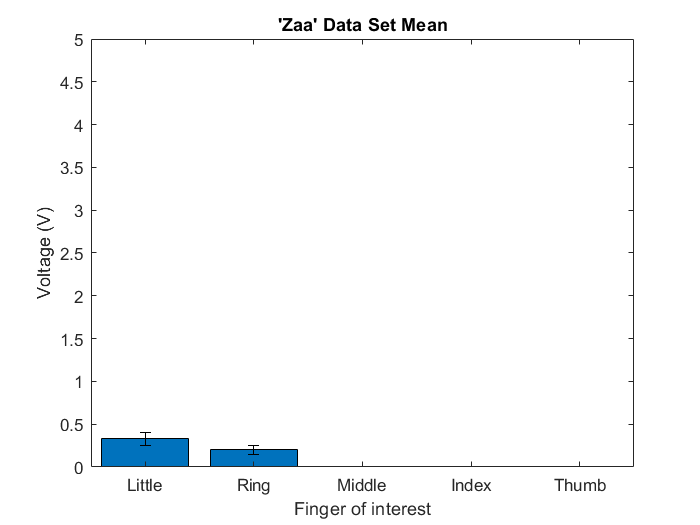



%W

w0=readmatrix("FlexiArSL.csv","Range","C102:C111");
w1=readmatrix("FlexiArSL.csv","Range","D102:D111");
w2=readmatrix("FlexiArSL.csv","Range","E102:E111");
w3=readmatrix("FlexiArSL.csv","Range","F102:F111");
w4=readmatrix("FlexiArSL.csv","Range","G102:G111");
w5=[mean(w0),mean(w1),mean(w2),mean(w3),mean(w4)];
werr=[std(w0),std(w1),std(w2),std(w3),std(w4)];
bar(names,w5)
hold on
er=errorbar(names,w5,werr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Zaa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

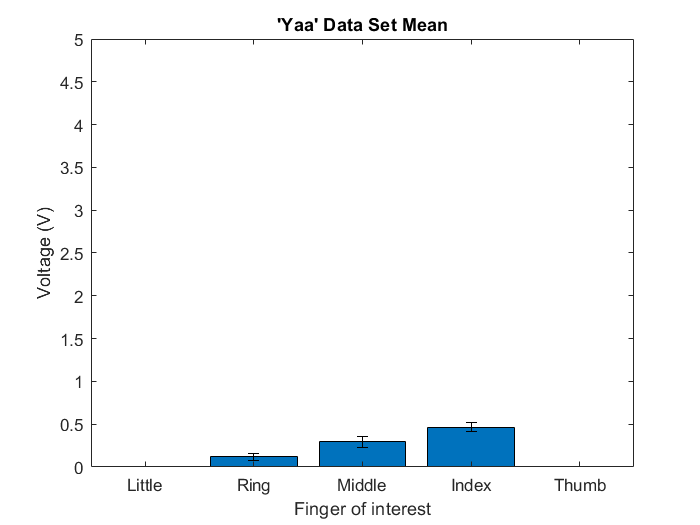



%Y

y0=readmatrix("FlexiArSL.csv","Range","C112:C121");
y1=readmatrix("FlexiArSL.csv","Range","D112:D121");
y2=readmatrix("FlexiArSL.csv","Range","E112:E121");
y3=readmatrix("FlexiArSL.csv","Range","F112:F121");
y4=readmatrix("FlexiArSL.csv","Range","G112:G121");
y5=[mean(y0),mean(y1),mean(y2),mean(y3),mean(y4)];
yerr=[std(y0),std(y1),std(y2),std(y3),std(y4)];
bar(names,y5)
hold on
er=errorbar(names,y5,yerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Yaa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

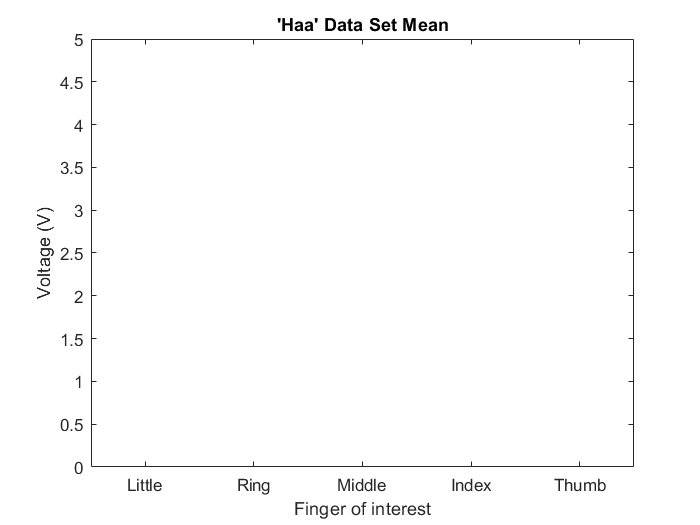



%ILY

ily0=readmatrix("FlexiArSL.csv","Range","C122:C131");
ily1=readmatrix("FlexiArSL.csv","Range","D122:D131");
ily2=readmatrix("FlexiArSL.csv","Range","E122:E131");
ily3=readmatrix("FlexiArSL.csv","Range","F122:F131");
ily4=readmatrix("FlexiArSL.csv","Range","G122:G131");
ily5=[mean(ily0),mean(ily1),mean(ily2),mean(ily3),mean(ily4)];
ilyerr=[std(ily0),std(ily1),std(ily2),std(ily3),std(ily4)];
bar(names,ily5)
hold on
er=errorbar(names,ily5,ilyerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Haa'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

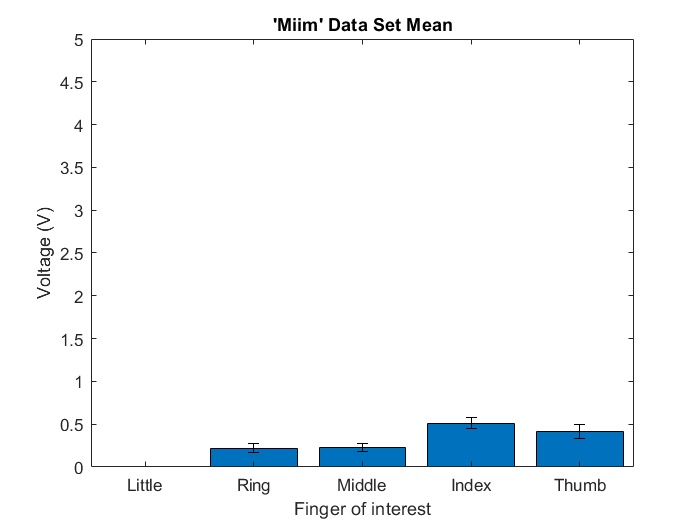



%Rock

rock0=readmatrix("FlexiArSL.csv","Range","C132:C141");
rock1=readmatrix("FlexiArSL.csv","Range","D132:D141");
rock2=readmatrix("FlexiArSL.csv","Range","E132:E141");
rock3=readmatrix("FlexiArSL.csv","Range","F132:F141");
rock4=readmatrix("FlexiArSL.csv","Range","G132:G141");
rock5=[mean(rock0),mean(rock1),mean(rock2),mean(rock3),mean(rock4)];
rockerr=[std(rock0),std(rock1),std(rock2),std(rock3),std(rock4)];
bar(names,rock5)
hold on
er=errorbar(names,rock5,rockerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Miim'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

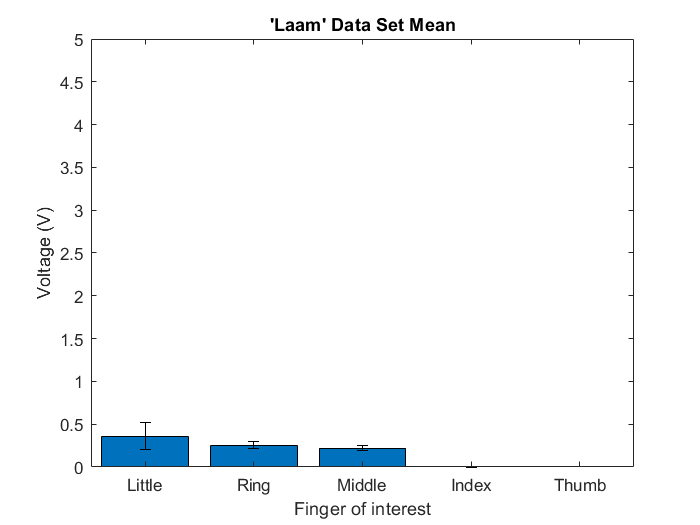



%7

sev0=readmatrix("FlexiArSL.csv","Range","C142:C151");
sev1=readmatrix("FlexiArSL.csv","Range","D142:D151");
sev2=readmatrix("FlexiArSL.csv","Range","E142:E151");
sev3=readmatrix("FlexiArSL.csv","Range","F142:F151");
sev4=readmatrix("FlexiArSL.csv","Range","G142:G151");
sev5=[mean(sev0),mean(sev1),mean(sev2),mean(sev3),mean(sev4)];
severr=[std(sev0),std(sev1),std(sev2),std(sev3),std(sev4)];
bar(names,sev5)
hold on
er=errorbar(names,sev5,severr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Laam'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off

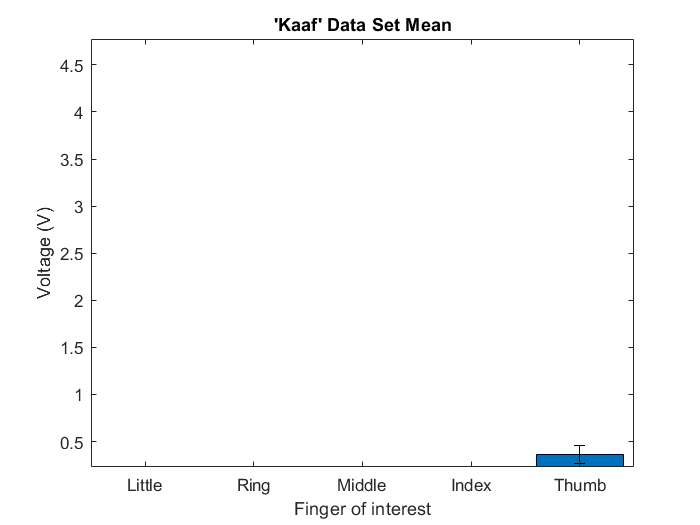



%8

eig0=readmatrix("FlexiArSL.csv","Range","C152:C161");
eig1=readmatrix("FlexiArSL.csv","Range","D152:D161");
eig2=readmatrix("FlexiArSL.csv","Range","E152:E161");
eig3=readmatrix("FlexiArSL.csv","Range","F152:F161");
eig4=readmatrix("FlexiArSL.csv","Range","G152:G161");
eig5=[mean(eig0),mean(eig1),mean(eig2),mean(eig3),mean(eig4)];
eigerr=[std(eig0),std(eig1),std(eig2),std(eig3),std(eig4)];
bar(names,eig5)
hold on
er=errorbar(names,eig5,eigerr);
er.Color = [0 0 0];
er.LineStyle = 'none';
ylim([0 5]);
title('''Kaaf'' Data Set Mean')
xlabel('Finger of interest')
ylabel('Voltage (V)')
hold off